load_data = false

load_data = logical
   0


% load_data = true

gen_header = false

gen_header = logical
   0


%gen_header = true

save_data = false

save_data = logical
   0


%save_data = true 

if load_data
load ryan4_battery_dataset.mat
load ryan4_data.mat
end

idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTest

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxTestSort

idxTestSort =     16    26    28    47    48    62    76    84    92    99   106   119


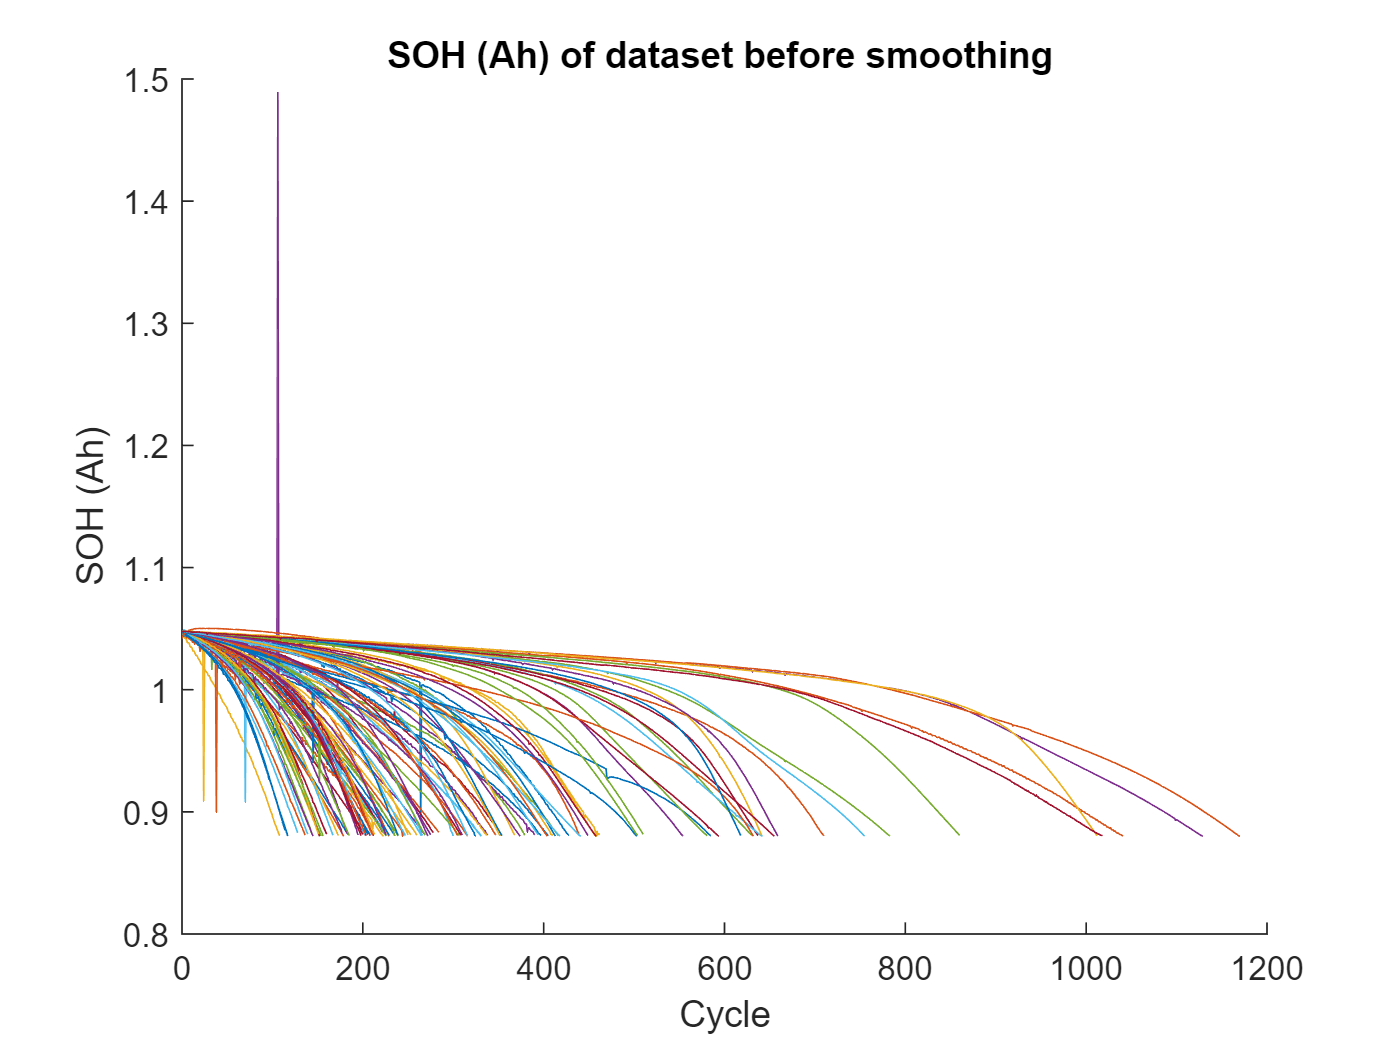

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;
nLines = length(idxAll);
idxTestCount = nLines;
%legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxAll(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischarge)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    %legend_str{j} = num2str(j) + ", " +num2str(i) + ", " + num2str(ryan4_battery_dataset(i).cycle_life);
    %pause(1)
end
ylabel 'SOH (Ah)'
xlabel 'Cycle'
hold off
title 'SOH (Ah) of dataset before smoothing '

%legend(legend_str)

for j = 1 : length(idxAll)
    
    if ryan4_battery_dataset(j).cycle_life < 316  & ryan4_battery_dataset(j).cycle_life > 300
    [j, ryan4_battery_dataset(j).cycle_life ]
    end

end

ans =     19   307


ans =     46   311


ans =     91   310


ans =     93   306


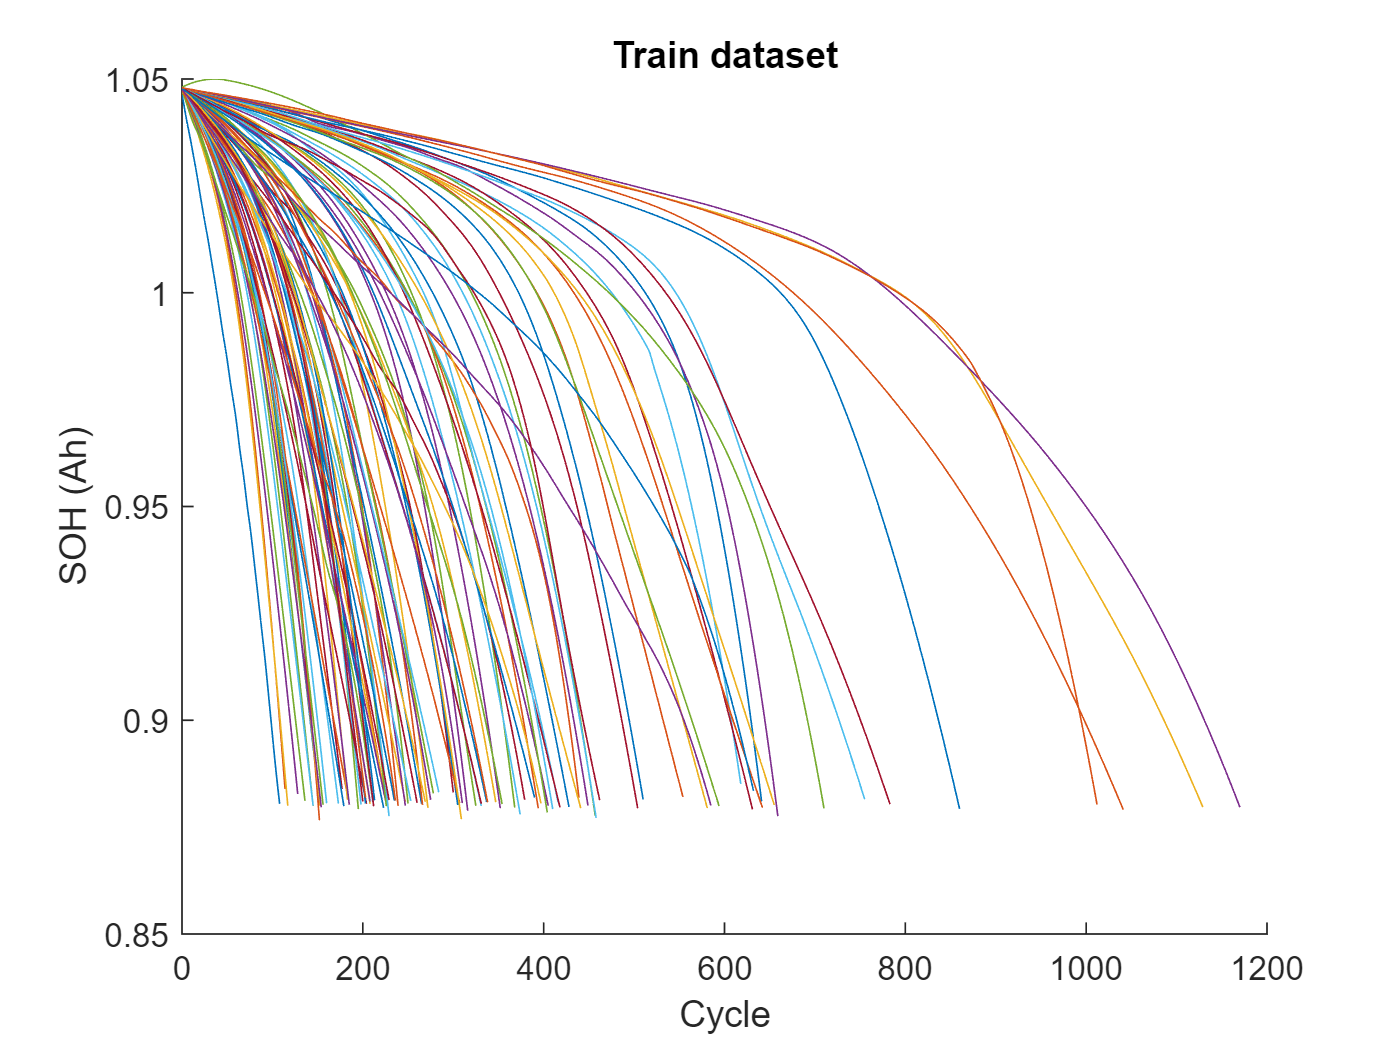

idxTrainValid = [idxTrain idxValid];
cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;
nLines = length(idxTrainValid);
idxTestCount = nLines;
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTrainValid(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    %legend_str{j} = num2str(j) + ", " +num2str(i) + ", " + num2str(ryan4_battery_dataset(i).cycle_life);
    %pause(1)
end
hold off
ylabel 'SOH (Ah)'
xlabel 'Cycle'
title 'Train dataset'

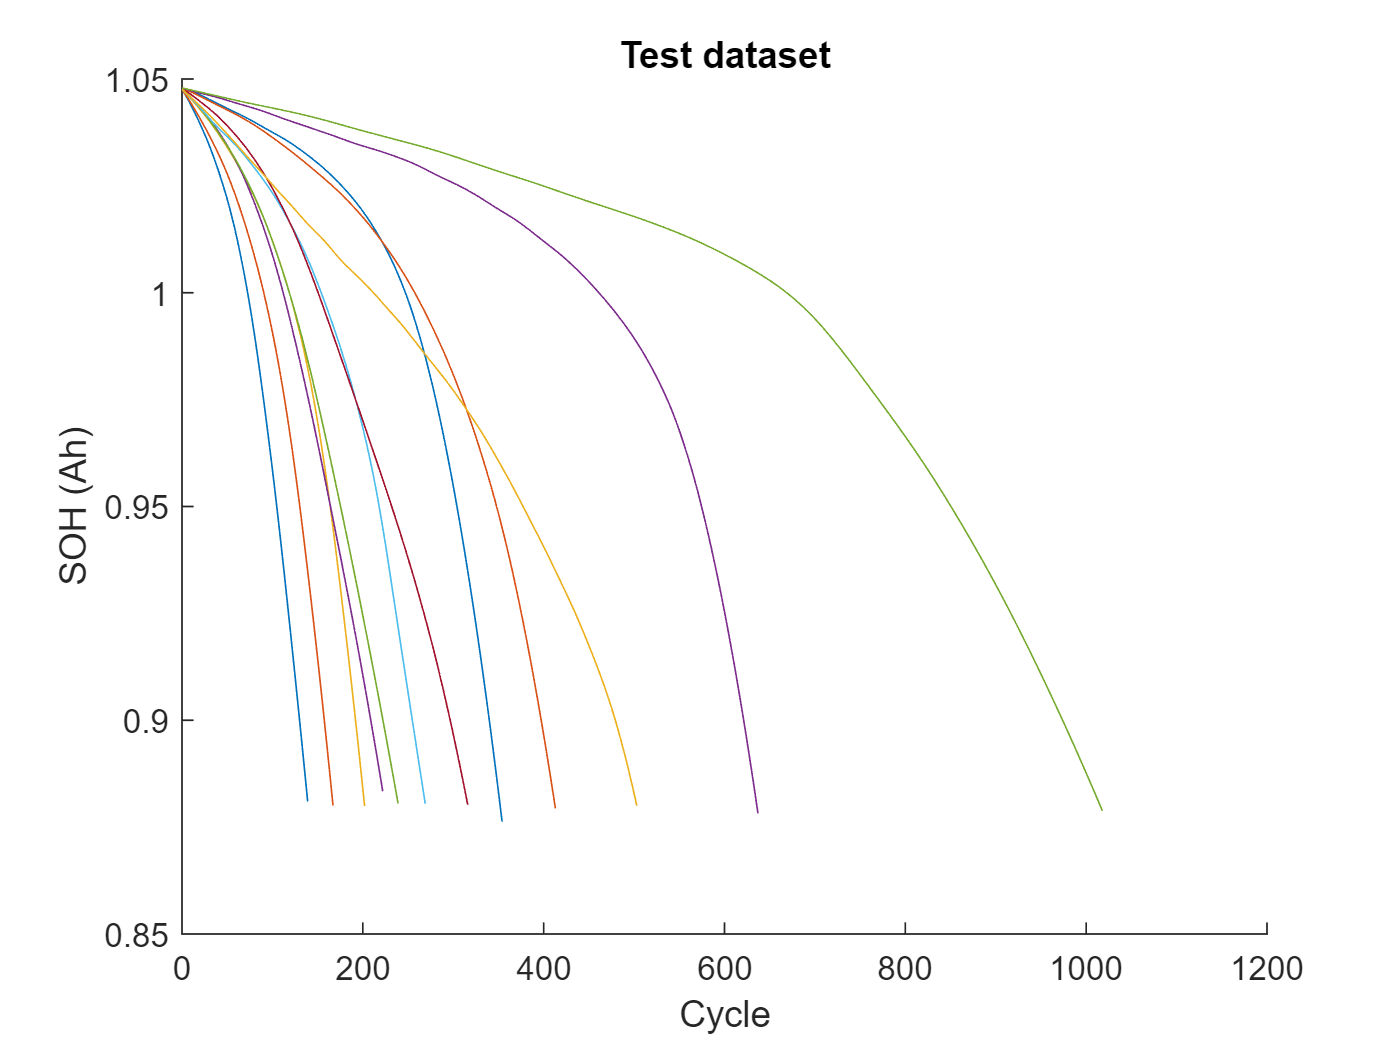

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;
nLines = length(idxTest);
idxTestCount = nLines;
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTest(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    %legend_str{j} = num2str(j) + ", " +num2str(i) + ", " + num2str(ryan4_battery_dataset(i).cycle_life);
    %pause(1)
end
hold off
ylabel 'SOH (Ah)'
xlabel 'Cycle'
title 'Test dataset'

%legend(legend_str)

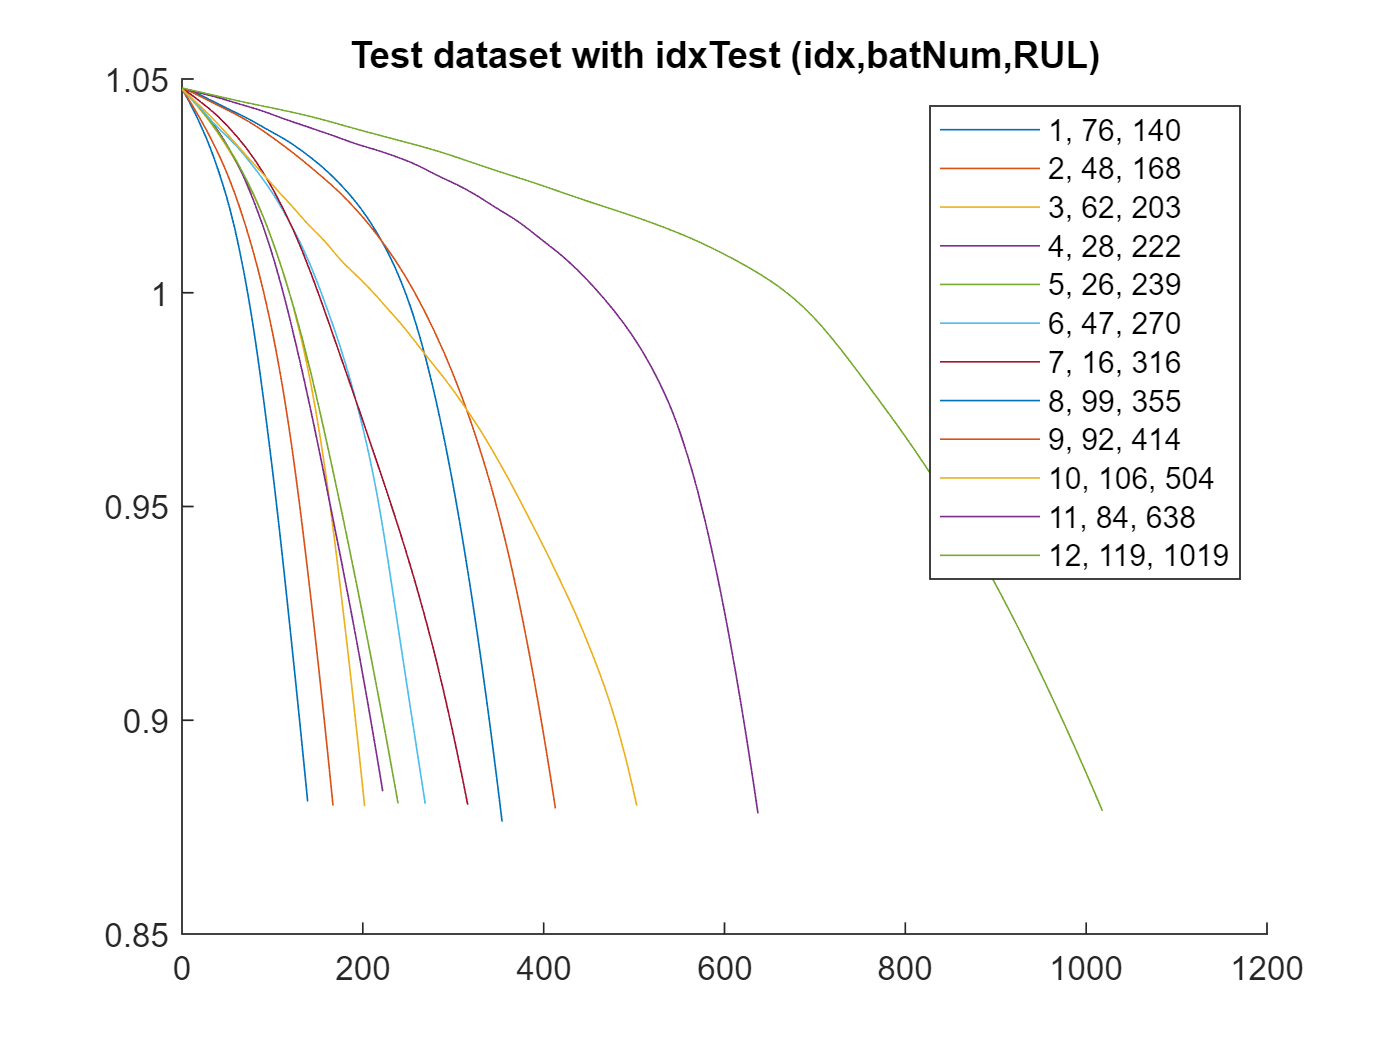

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;
nLines = length(idxTest);
idxTestCount = nLines;
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTest(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    legend_str{j} = num2str(j) + ", " +num2str(i) + ", " + num2str(ryan4_battery_dataset(i).cycle_life);
    %pause(1)
end
hold off
title 'Test dataset with idxTest (idx,batNum,RUL)'
legend(legend_str)

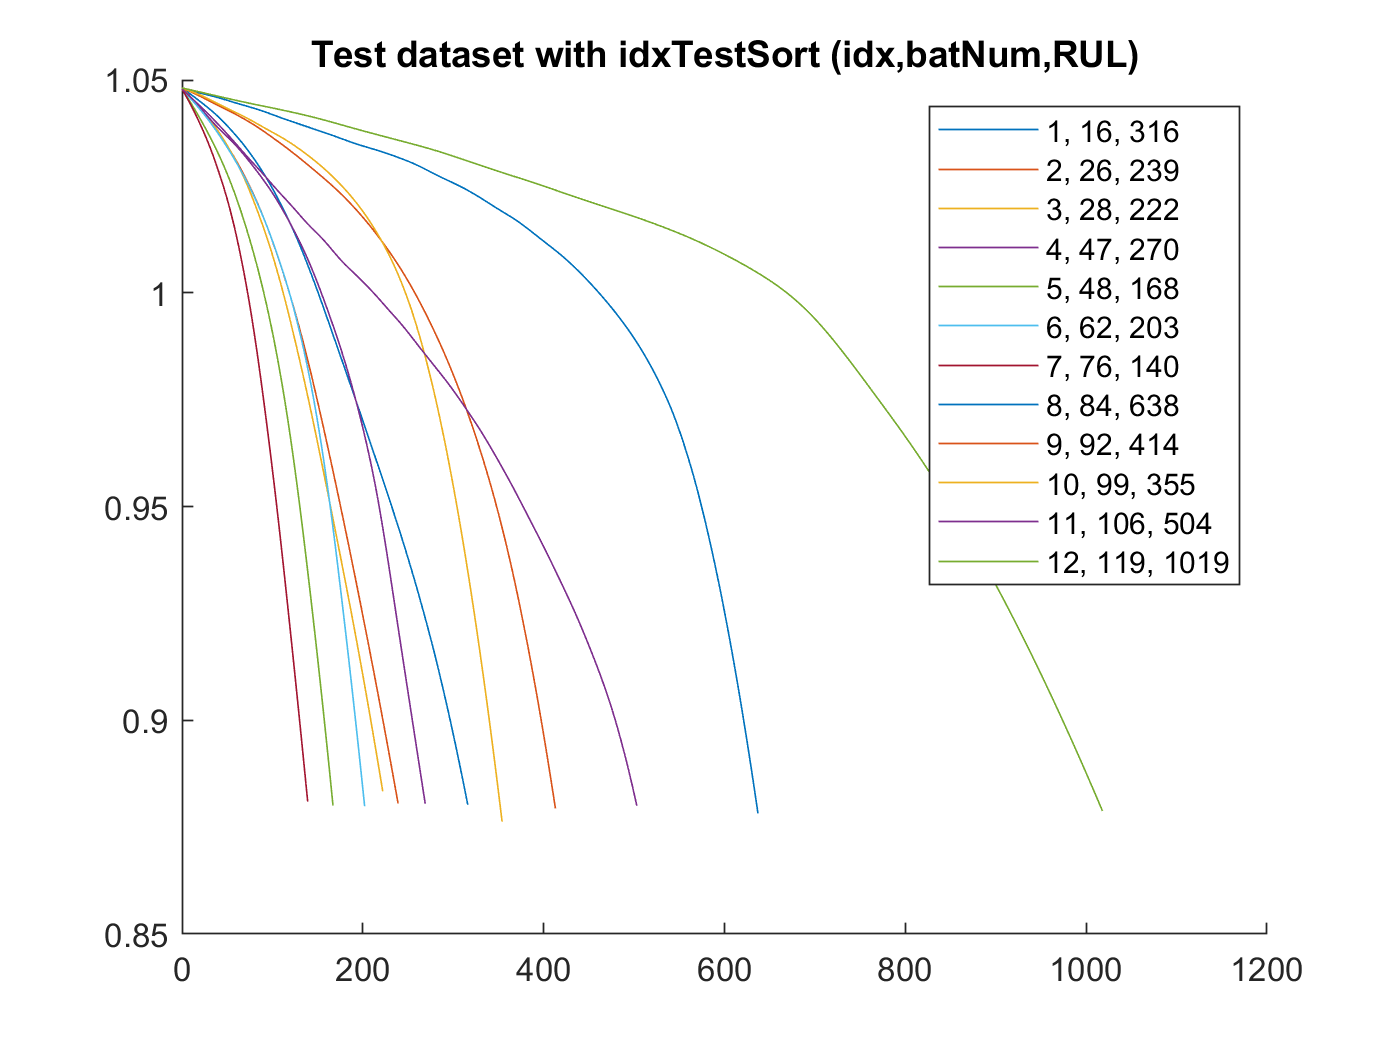


cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;
nLines = length(idxTestSort);
idxTestCount = nLines;
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTestSort(j);
    plot(ryan4_battery_dataset(i).cycle,ryan4_battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i ryan4_battery_dataset(i).cycle_life];
    legend_str{j} = num2str(j) + ", " +num2str(i) + ", " + num2str(ryan4_battery_dataset(i).cycle_life);
    pause(1)
end
hold off
title 'Test dataset with idxTestSort (idx,batNum,RUL)'
legend(legend_str)


fprintf(">> test data set based on each measure point <<")

>> test data set based on each measure point <<


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011



fprintf(">> find out battery index of each point <<")

>> find out battery index of each point <<

idxTestAll_batIndex

idxTestAll_batIndex =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


fprintf(">> find out each point of battery index 16 <<")

>> find out each point of battery index 16 <<

idxTestAll_batIndex1 = (idxTestAll_batIndex == 16)

idxTestAll_batIndex1 = 1×4488 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1



find(idxTestAll_batIndex == idxTest(7))

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


find(idxTestAll_batIndex == idxTestSort(1))

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTestAll_idx1_bat16 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)))

idxTestAll_idx1_bat16 =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


idxTestAll_idx1_bat16_1 = idxTestAll(find(idxTestAll_batIndex == idxTestSort(1)))

idxTestAll_idx1_bat16_1 =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011



RUL(idxTestAll_idx1_bat16)

ans =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


test_idx1_bat16 = idxTest(7)

test_idx1_bat16 = 16

RUL_idx1_bat16 = RUL(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)))

RUL_idx1_bat16 =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


ynorm_RUL_idx1_bat16 = ynorm_RUL(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)))

ynorm_RUL_idx1_bat16 =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


SOH_idx1_bat16 = Cap(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)))

SOH_idx1_bat16 =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


ynorm_SOH_idx1_bat16 = ynorm_SOH(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)))

ynorm_SOH_idx1_bat16 =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791



Ic_idx1_bat16 = Ic(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)),:)

Ic_idx1_bat16 =     6.0003    6.0001    5.9997    6.0001    5.9999    6.0006    5.9998    4.1998    3.0000    3.0000    3.0000    2.9999    3.0000    3.0001    2.1289    0.9999    1.0000    0.2383         0         0
    6.0008    6.0005    5.9999    5.9998    5.9997    6.0005    5.9999    4.2002    3.0001    3.0000    3.0000    2.9999    3.0000    3.0000    2.1270    1.0000    1.0000    0.2294         0         0
    5.9998    6.0000    6.0006    6.0002    6.0002    5.9997    6.0003    4.1997    3.0000    3.0000    3.0000    2.9999    3.0002    3.0000    2.1257    1.0000    0.9998    0.2293         0         0
    6.0008    6.0002    5.9999    5.9997    6.0007    6.0004    6.0004    4.1998    3.0002    3.0000    3.0000    3.0000    2.9999    3.0000    2.1274    1.0000    1.0000    0.2238         0         0
    6.0008    6.0002    6.0002    6.0003    6.0001    5.9999    5.9998    4.1998    3.0001    3.0000    2.9999    2.9998    3.0000    3.0000    2.1282    1.0000    0.9999    0.2214

Vd_idx1_bat16 = Vd(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)),:)

Vd_idx1_bat16 =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.9999

xnorm_Vd_idx1_bat16 = xnorm_Vd(idxTestAll(find(idxTestAll_batIndex == test_idx1_bat16)),:)

xnorm_Vd_idx1_bat16 =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    

ytrain = ynorm_RUL_idx1_bat16 ;
Xtrain = xnorm_Vd_idx1_bat16 ;
Ytrain = RUL_idx1_bat16 ;
Ytrain_soh = SOH_idx1_bat16 ;

len_1  =  length(RUL_idx1_bat16 ) - mod(length(RUL_idx1_bat16 ),5) ; 

len = length(ynorm_RUL_idx1_bat16) ;
Xtrain = Xtrain(1:len_1,:);
ytrain = ytrain(1:len_1,:);
Ytrain = Ytrain(1:len_1,:);
Ytrain_soh = Ytrain_soh(1:len_1,:);




idxSearch_idx1_bat16 = 1; % 316
idxSearch_idx2_bat26 = 2; % 239

idxFind = idxTest(find(idxTest == idxTestSort(idxSearch_idx1_bat16)));
idxFindAll = find(idxTestAll_batIndex == idxFind);
Y_test_RUL_idx1_bata16 = Y_test_RUL(idxFindAll);
Y_test_RUL_idx1_bat16 = Y_test_SOH(idxFindAll);
% Yfit_test_RUL_test1 = Yfit_test_RUL(idxFindAll);

compareTo = Y_test_RUL_idx1_bata16(1)

compareTo = 316


idx = idxTestSort(idxSearch_idx1_bat16) %16

idx = 16

% find most similar data
idxTrainValid = [idxTrain idxValid]

idxTrainValid =     38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25    27    33    53     2    22     8    57    23    55    45     3    17    34    41   109    18     7     9    13    93



count = length(idxTrain) + length(idxValid)

count = 107

idxSel = 0;
diff = 1000;
for i=1:count 
    diff_new = abs( ryan4_battery_dataset(idxTrainValid(i)).cycle_life - compareTo );
    if diff_new < diff 
        idxSel = idxTrainValid(i);
        diff = diff_new;
    end
end


matchedRUL = ryan4_battery_dataset(idxSel).cycle_life

matchedRUL = 317

inTrain = any(idxTrain==idxSel)

inTrain = logical
   1



if inTrain
    idxFindSel = idxTest(find(idxTest == idxTestSort(idxSearch_idx1_bat16)));
    idxFindAllSel = find(idxTestAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
else
    idxFindSel = idxTest(find(idxValid == idxValidSort(idxSearch)));
    idxFindAllSel = find(idxValidAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
end 


ytrainSim = y_test_RUL_Sel1;

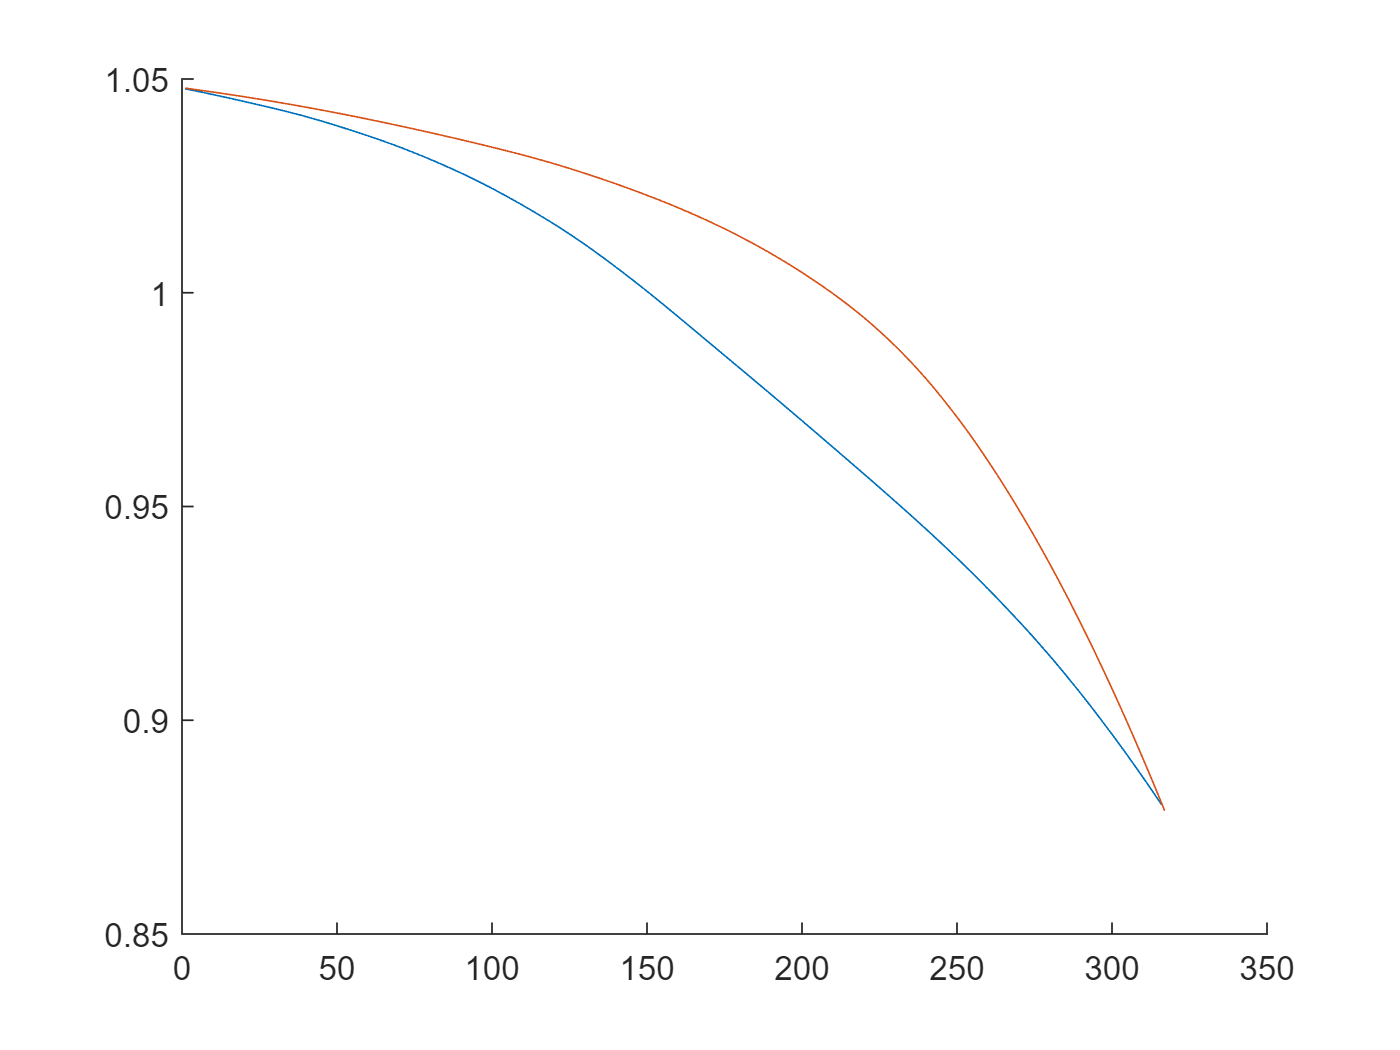

figure, hold on
plot(ryan4_battery_dataset(idx).QDischargeSmooth)
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth)
hold off



idxFind2 = idxTest(find(idxTest == idxTestSort(idxSearch_idx2_bat26)));
idxFindAll2 = find(idxTestAll_batIndex == idxFind2);
Y_test_RUL_test2 = Y_test_RUL(idxFindAll2);
% Yfit_test_RUL_test2 = Yfit_test_RUL(idxFindAll2);

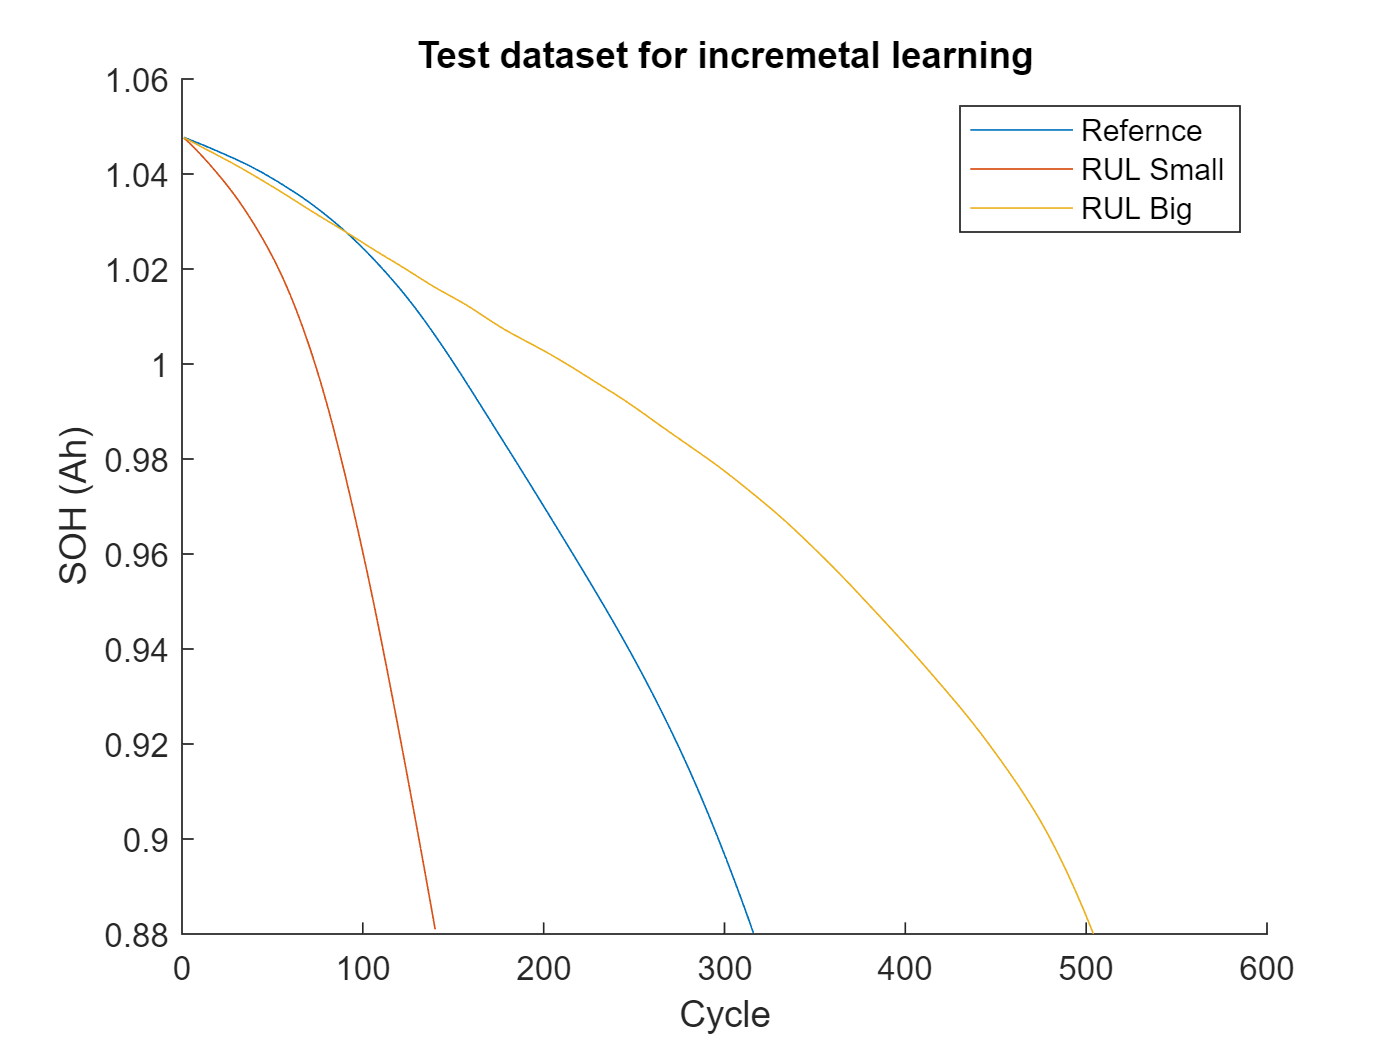

%load robotarm
idxTest ;
count = length(idxTest) ;

for i=1:count 
   [i idxTest(i) ryan4_battery_dataset(idxTest(i)).cycle_life ] ;
end

% 1 76  140 
% 7 16  316
% 10 106 504
%% 11 84 638

figure, hold on
plot( ryan4_battery_dataset(idxTest(7)).QDischargeSmooth )
plot( ryan4_battery_dataset(idxTest(1)).QDischargeSmooth )
plot( ryan4_battery_dataset(idxTest(10)).QDischargeSmooth )
hold off
ylabel('SOH (Ah)')
xlabel('Cycle')
legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'RUL Small';
legend_str{3} = 'RUL Big';
legend(legend_str)
title 'Test dataset for incremetal learning'

for j = 1 : length(idxAll)
    
    if ryan4_battery_dataset(j).cycle_life < 316  & ryan4_battery_dataset(j).cycle_life > 300
    [j, ryan4_battery_dataset(j).cycle_life ]
    end

end

ans =     19   307


ans =     46   311


ans =     91   310


ans =     93   306


idxTest(7)

ans = 16

ryan4_battery_dataset(idxTest(7)).cycle_life

ans = 316



ryan4_util_global

[ref_bat_index, ref_bat_rul,ref_bat_index_2nd, ref_bat_rul_2nd ] = ryan4_util_find_similar_bat_with_rul(idxTest(7))

ref_bat_index = 118

ref_bat_rul = 317

ref_bat_index_2nd = 46

ref_bat_rul_2nd = 311


batNum_base = idxTest(7)

batNum_base = 16

batNum_ref = (ref_bat_index)

batNum_ref = 118

batNum_ref_2nd = (ref_bat_index_2nd)

batNum_ref_2nd = 46

%%%%%%%%%%%%%%%%%%%%%%%
ref_bat_index_2nd = 93

ref_bat_index_2nd = 93

ref_bat_rul_2nd = ryan4_battery_dataset(ref_bat_index_2nd).cycle_life

ref_bat_rul_2nd = 306


batNum_ref_2nd = (ref_bat_index_2nd)

batNum_ref_2nd = 93

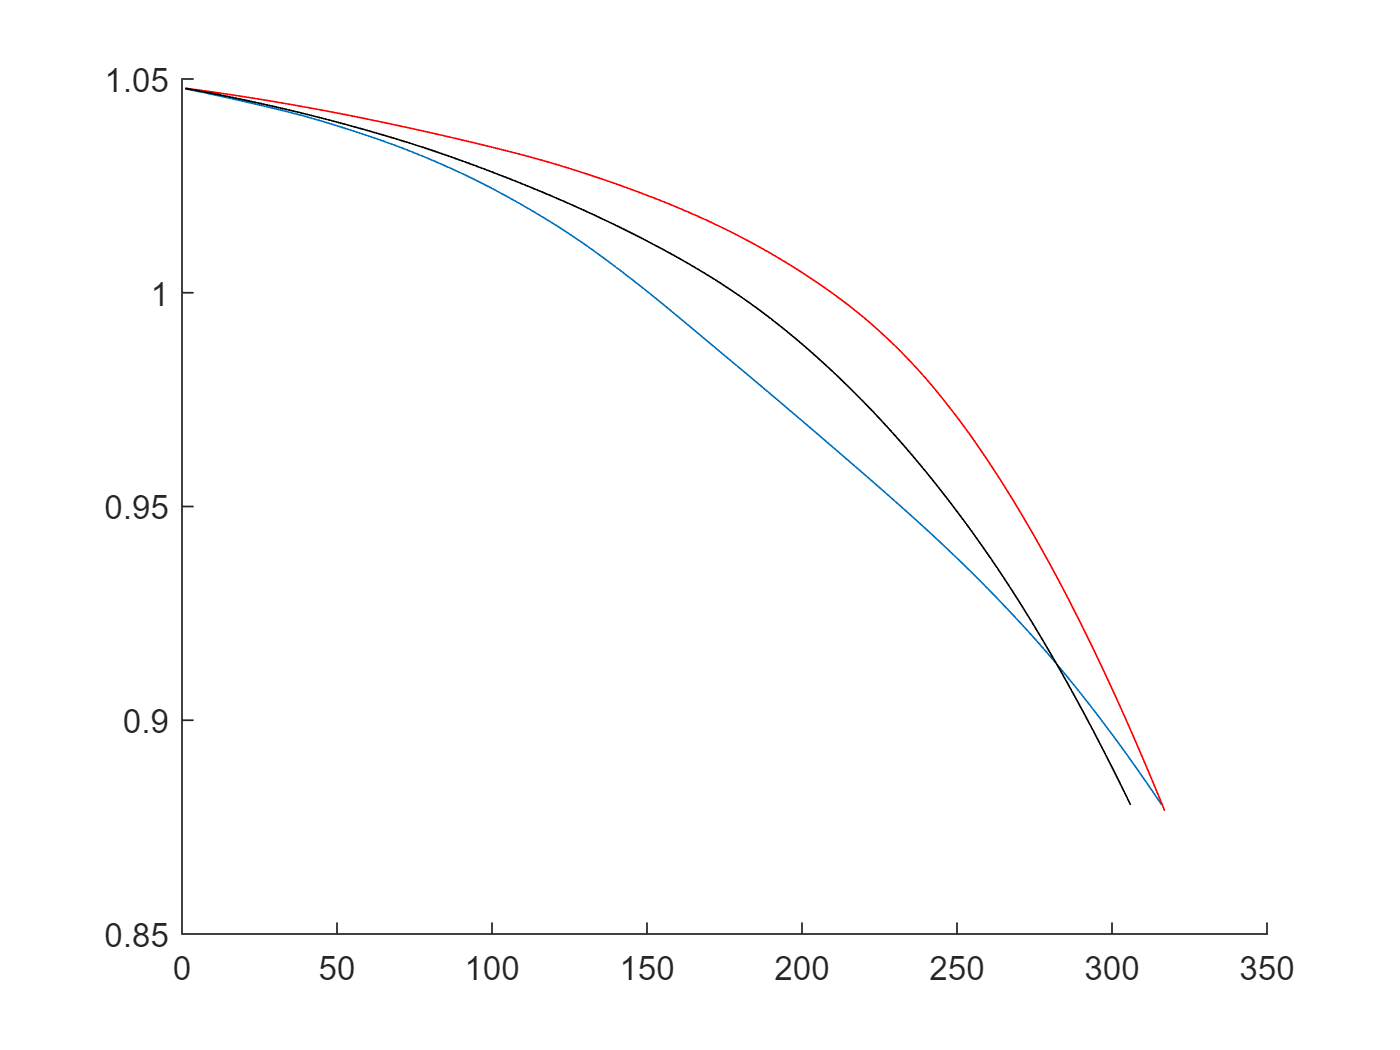



%%%%%%%%%%%%%%%%%%%%%%%%


figure, hold on
plot(ryan4_battery_dataset(batNum_base).QDischargeSmooth)
plot(ryan4_battery_dataset(batNum_ref).QDischargeSmooth,'r')
plot(ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth,'k')
hold off

for i=1:length(ryan4_battery_dataset(batNum_base).cycle)
 if ryan4_battery_dataset(batNum_base).QDischargeSmooth(i) < Cap_change 
    break
 end
end 
batNum_base_pre_idx = i;

for i=1:length(ryan4_battery_dataset(batNum_ref).cycle)
 if ryan4_battery_dataset(batNum_ref).QDischargeSmooth(i) < Cap_change 
    break
 end
end 
batNum_ref_pre_idx = i;

for i=1:length(ryan4_battery_dataset(batNum_ref_2nd).cycle)
 if ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(i) < Cap_change 
    break
 end
end 
batNum_ref_2nd_pre_idx = i;

%test_data_2_bast_match_SOH_pre = [ryan4_battery_dataset(batNum_ref).QDischargeSmooth(ref_bat_cross:end)];
%test_data_2_2nd_match_SOH_pre = [ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(ref_bat_cross_2nd:end)];

scenario_7_test_data_2_base_SOH_pre = [ryan4_battery_dataset(batNum_base).QDischargeSmooth(1:batNum_base_pre_idx)];
scenario_7_test_data_2_base_SOH_post = [ryan4_battery_dataset(batNum_base).QDischargeSmooth(batNum_base_pre_idx+1:end)];

scenario_7_test_data_2_bestMatch_SOH_pre = [ryan4_battery_dataset(batNum_ref).QDischargeSmooth(1:batNum_ref_pre_idx)];
scenario_7_test_data_2_2ndMatch_SOH_pre = [ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(1:batNum_ref_2nd_pre_idx)];

scenario_7_test_data_2_bestMatch_RUL_pre = linspace(ryan4_battery_dataset(batNum_ref).cycle_life, ...
    ryan4_battery_dataset(batNum_ref).cycle_life - length(scenario_7_test_data_2_bestMatch_SOH_pre) + 1 , ... 
    length(scenario_7_test_data_2_bestMatch_SOH_pre ) )

scenario_7_test_data_2_bestMatch_RUL_pre =    317   316   315   314   313   312   311   310   309   308   307   306   305   304   303   302   301   300   299   298   297   296   295   294   293   292   291   290   289   288   287   286   285   284   283   282   281   280   279   278   277   276   275   274   273   272   271   270   269   268


scenario_7_test_data_2_2ndMatch_RUL_pre = linspace(ryan4_battery_dataset(batNum_ref_2nd).cycle_life, ...
    ryan4_battery_dataset(batNum_ref_2nd).cycle_life - length(scenario_7_test_data_2_2ndMatch_SOH_pre) + 1 , ... 
    length(scenario_7_test_data_2_2ndMatch_SOH_pre ) )

scenario_7_test_data_2_2ndMatch_RUL_pre =    306   305   304   303   302   301   300   299   298   297   296   295   294   293   292   291   290   289   288   287   286   285   284   283   282   281   280   279   278   277   276   275   274   273   272   271   270   269   268   267   266   265   264   263   262   261   260   259   258   257


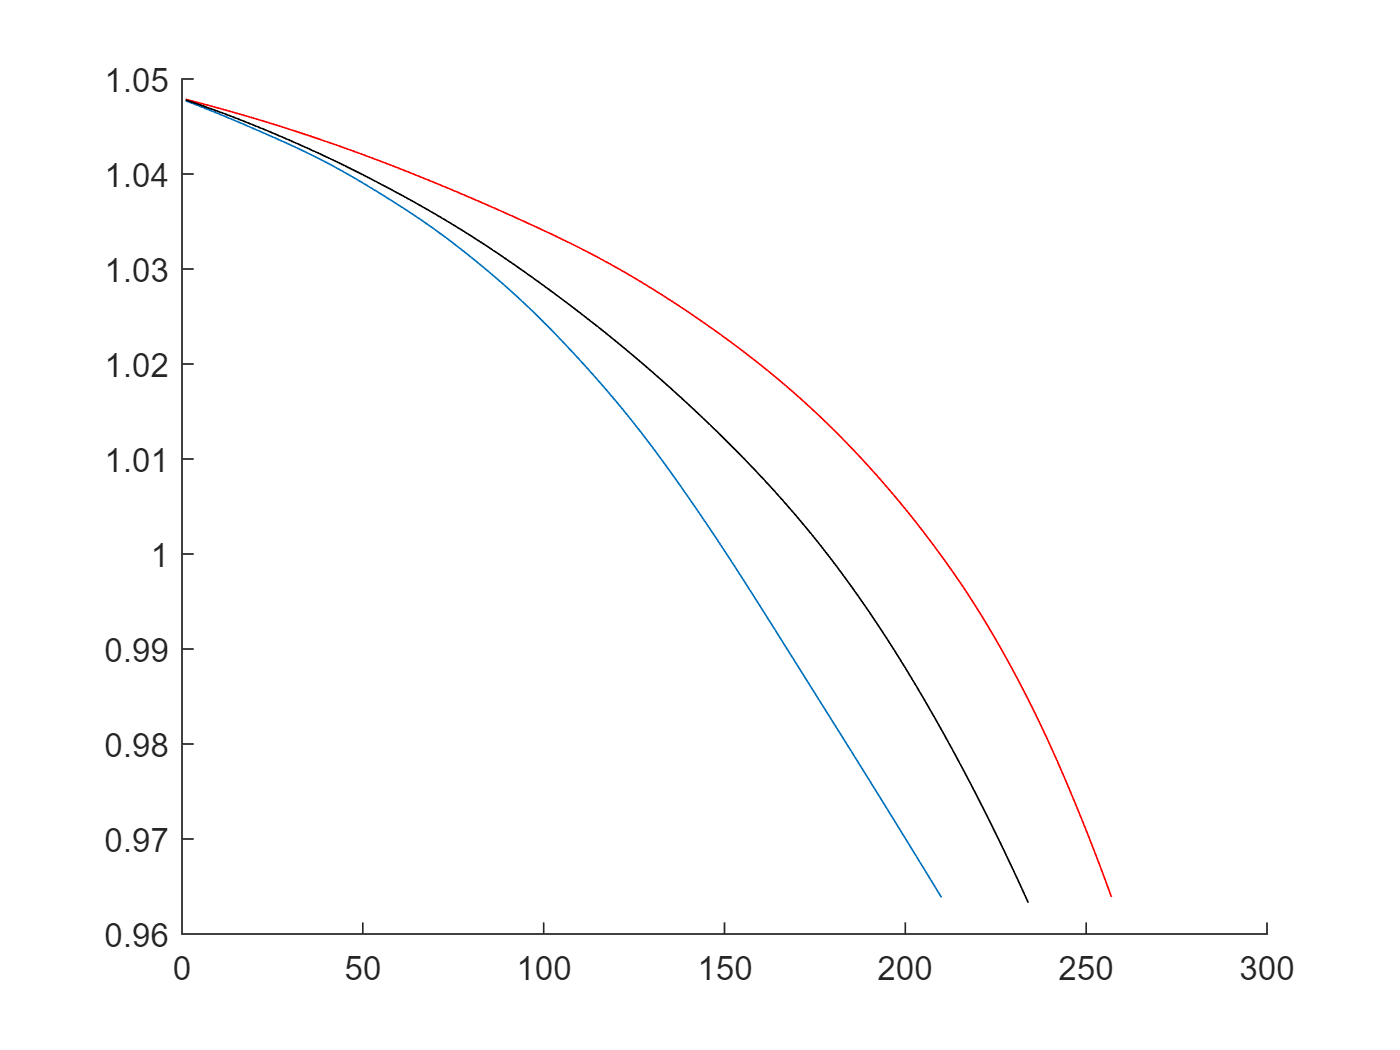



figure, hold on
plot(scenario_7_test_data_2_base_SOH_pre)
plot(scenario_7_test_data_2_bestMatch_SOH_pre,'r')
plot(scenario_7_test_data_2_2ndMatch_SOH_pre,'k')
hold off

scenario_7_test_data_2_base_SOH = [ scenario_7_test_data_2_base_SOH_pre ; scenario_7_test_data_2_base_SOH_post ];
scenario_7_test_data_2_base_RUL = linspace(ryan4_battery_dataset(batNum_base).cycle_life, ...
    1 , ... 
    length(scenario_7_test_data_2_base_SOH ) )

scenario_7_test_data_2_base_RUL =    316   315   314   313   312   311   310   309   308   307   306   305   304   303   302   301   300   299   298   297   296   295   294   293   292   291   290   289   288   287   286   285   284   283   282   281   280   279   278   277   276   275   274   273   272   271   270   269   268   267


Cap_change = (Cap_Rated + Cap_EOL ) / 2 ;

[idx1change] = find(ryan4_battery_dataset(idxTest(1)).QDischargeSmooth >= Cap_change,1,'last') ;
[idx2change] = find(ryan4_battery_dataset(idxTest(7)).QDischargeSmooth >= Cap_change,1,'last') ;
[idx3change] = find(ryan4_battery_dataset(idxTest(10)).QDischargeSmooth >= Cap_change,1,'last') ;


idx1_RUL_count = ryan4_battery_dataset(idxTest(1)).cycle_life

idx1_RUL_count = 140

idx1_RUL_all   = linspace(idx1_RUL_count,idx1_RUL_count,idx1_RUL_count)'

idx1_RUL_all =    140
   140
   140
   140
   140
   140
   140
   140
   140
   140


idx1_RUL_pre   = linspace(idx1_RUL_count,idx1_RUL_count-idx1change+1,idx1change)' 

idx1_RUL_pre =    140
   139
   138
   137
   136
   135
   134
   133
   132
   131


idx1_RUL_post  = linspace(idx1_RUL_count-idx1change ,1,idx1_RUL_count-idx1change)'

idx1_RUL_post =     43
    42
    41
    40
    39
    38
    37
    36
    35
    34



length(idx1_RUL_all)

ans = 140

length(idx1_RUL_pre)

ans = 97

length(idx1_RUL_post)

ans = 43


idx1_RUL_pre(1)

ans = 140

idx1_RUL_pre(end)

ans = 44

idx1_RUL_post(1)

ans = 43

idx1_RUL_post(end)

ans = 1




idx2_RUL_count = ryan4_battery_dataset(idxTest(7)).cycle_life

idx2_RUL_count = 316

idx2_RUL_all   = linspace(idx2_RUL_count,idx2_RUL_count,idx2_RUL_count)'

idx2_RUL_all =    316
   316
   316
   316
   316
   316
   316
   316
   316
   316


idx2_RUL_pre   = linspace(idx2_RUL_count,idx2_RUL_count-idx2change+1,idx2change)' 

idx2_RUL_pre =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


idx2_RUL_post  = linspace(idx2_RUL_count-idx2change ,1,idx2_RUL_count-idx2change)'

idx2_RUL_post =    107
   106
   105
   104
   103
   102
   101
   100
    99
    98



length(idx2_RUL_all)

ans = 316

length(idx2_RUL_pre)

ans = 209

length(idx2_RUL_post)

ans = 107


idx2_RUL_pre(1)

ans = 316

idx2_RUL_pre(end)

ans = 108

idx2_RUL_post(1)

ans = 107

idx2_RUL_post(end)

ans = 1



idx3_RUL_count = ryan4_battery_dataset(idxTest(10)).cycle_life

idx3_RUL_count = 504

idx3_RUL_all   = linspace(idx3_RUL_count,idx3_RUL_count,idx3_RUL_count)'

idx3_RUL_all =    504
   504
   504
   504
   504
   504
   504
   504
   504
   504


idx3_RUL_pre   = linspace(idx3_RUL_count,idx3_RUL_count-idx3change+1,idx3change)' 

idx3_RUL_pre =    504
   503
   502
   501
   500
   499
   498
   497
   496
   495


idx3_RUL_post  = linspace(idx3_RUL_count-idx3change ,1,idx3_RUL_count-idx3change)'

idx3_RUL_post =    163
   162
   161
   160
   159
   158
   157
   156
   155
   154



length(idx3_RUL_all)

ans = 504

length(idx3_RUL_pre)

ans = 341

length(idx3_RUL_post)

ans = 163


idx3_RUL_pre(1)

ans = 504

idx3_RUL_pre(end)

ans = 164

idx3_RUL_post(1)

ans = 163

idx3_RUL_post(end)

ans = 1




ryan4_change_21RulOrg = [idx2_RUL_pre ; idx1_RUL_post ]

ryan4_change_21RulOrg =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


ryan4_change_23RulOrg = [idx2_RUL_pre ; idx3_RUL_post ]

ryan4_change_23RulOrg =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307



ryan4_change_11Qd = ryan4_battery_dataset(idxTest(1)).QDischargeSmooth

ryan4_change_11Qd =     1.0476
    1.0473
    1.0469
    1.0465
    1.0462
    1.0458
    1.0454
    1.0450
    1.0446
    1.0442


ryan4_change_22Qd = ryan4_battery_dataset(idxTest(7)).QDischargeSmooth

ryan4_change_22Qd =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


ryan4_change_33Qd = ryan4_battery_dataset(idxTest(10)).QDischargeSmooth

ryan4_change_33Qd =     1.0477
    1.0475
    1.0473
    1.0471
    1.0469
    1.0467
    1.0465
    1.0463
    1.0461
    1.0459


ryan4_change_21Qd = [ ryan4_change_22Qd(1:idx2change) ; ryan4_change_11Qd(idx1change+1:end) ]

ryan4_change_21Qd =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


ryan4_change_23Qd = [ ryan4_change_22Qd(1:idx2change) ; ryan4_change_33Qd(idx3change+1:end) ]

ryan4_change_23Qd =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464



ryan4_change_11VdFull = ryan4_battery_dataset(idxTest(1)).Vd;
ryan4_change_22VdFull = ryan4_battery_dataset(idxTest(7)).Vd;
ryan4_change_33VdFull = ryan4_battery_dataset(idxTest(10)).Vd;
ryan4_change_21VdFull = vertcat( ryan4_change_22VdFull(1:idx2change,:) , ryan4_change_11VdFull(idx1change+1:end,:) )

ryan4_change_21VdFull =     3.3035    3.2409    3.2095    3.1927    3.1825    3.1759    3.1710    3.1672    3.1640    3.1613    3.1585    3.1562    3.1539    3.1518    3.1498    3.1475    3.1458    3.1437    3.1418    3.1397    3.1376    3.1354    3.1333    3.1313    3.1291    3.1269    3.1246    3.1223    3.1198    3.1176    3.1151    3.1125    3.1104    3.1075    3.1049    3.1024    3.0996    3.0970    3.0942    3.0914    3.0886    3.0857    3.0828    3.0799    3.0768    3.0736    3.0703    3.0671    3.0635    3.0599
    3.3032    3.2402    3.2090    3.1921    3.1820    3.1754    3.1705    3.1668    3.1635    3.1607    3.1581    3.1560    3.1536    3.1514    3.1492    3.1474    3.1453    3.1432    3.1411    3.1392    3.1371    3.1350    3.1330    3.1307    3.1285    3.1262    3.1241    3.1218    3.1195    3.1170    3.1146    3.1120    3.1096    3.1070    3.1044    3.1019    3.0993    3.0965    3.0937    3.0910    3.0879    3.0851    3.0823    3.0793    3.0764    3.0730    3.0699    3

ryan4_change_23VdFull = vertcat( ryan4_change_22VdFull(1:idx2change,:) , ryan4_change_33VdFull(idx3change+1:end,:) )

ryan4_change_23VdFull =     3.3035    3.2409    3.2095    3.1927    3.1825    3.1759    3.1710    3.1672    3.1640    3.1613    3.1585    3.1562    3.1539    3.1518    3.1498    3.1475    3.1458    3.1437    3.1418    3.1397    3.1376    3.1354    3.1333    3.1313    3.1291    3.1269    3.1246    3.1223    3.1198    3.1176    3.1151    3.1125    3.1104    3.1075    3.1049    3.1024    3.0996    3.0970    3.0942    3.0914    3.0886    3.0857    3.0828    3.0799    3.0768    3.0736    3.0703    3.0671    3.0635    3.0599
    3.3032    3.2402    3.2090    3.1921    3.1820    3.1754    3.1705    3.1668    3.1635    3.1607    3.1581    3.1560    3.1536    3.1514    3.1492    3.1474    3.1453    3.1432    3.1411    3.1392    3.1371    3.1350    3.1330    3.1307    3.1285    3.1262    3.1241    3.1218    3.1195    3.1170    3.1146    3.1120    3.1096    3.1070    3.1044    3.1019    3.0993    3.0965    3.0937    3.0910    3.0879    3.0851    3.0823    3.0793    3.0764    3.0730    3.0699    3


% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))



ryan4_change_11Vd = blockproc(ryan4_change_11VdFull, blockSize, meanFilterFunction)

ryan4_change_11Vd =     3.2126    3.1534    3.1381    3.1265    3.1147    3.1020    3.0882    3.0731    3.0559    3.0355    3.0098    2.9756    2.9247    2.8420    2.6949    2.4128    2.0000    2.0000    2.0000    2.0000
    3.2136    3.1548    3.1397    3.1281    3.1165    3.1040    3.0906    3.0757    3.0590    3.0390    3.0144    2.9805    2.9309    2.8506    2.7076    2.4402    2.0000    2.0002    2.0003    2.0003
    3.2120    3.1531    3.1376    3.1257    3.1138    3.1014    3.0875    3.0728    3.0555    3.0355    3.0100    2.9762    2.9257    2.8437    2.6977    2.4178    2.0000    1.9999    1.9997    1.9997
    3.2123    3.1532    3.1379    3.1260    3.1141    3.1015    3.0876    3.0724    3.0553    3.0346    3.0091    2.9744    2.9228    2.8391    2.6899    2.3949    2.0000    2.0001    2.0002    2.0002
    3.2128    3.1531    3.1377    3.1256    3.1139    3.1013    3.0877    3.0731    3.0560    3.0364    3.0115    2.9780    2.9277    2.8465    2.7013    2.4262    1.9999    2.

ryan4_change_22Vd = blockproc(ryan4_change_22VdFull, blockSize, meanFilterFunction)

ryan4_change_22Vd =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.

ryan4_change_33Vd = blockproc(ryan4_change_33VdFull, blockSize, meanFilterFunction)

ryan4_change_33Vd =     3.2365    3.1836    3.1705    3.1604    3.1507    3.1406    3.1295    3.1175    3.1047    3.0914    3.0767    3.0599    3.0394    3.0131    2.9753    2.9079    2.7298    2.0791    2.0000    2.0000
    3.2364    3.1834    3.1703    3.1602    3.1506    3.1404    3.1294    3.1173    3.1045    3.0911    3.0765    3.0596    3.0391    3.0127    2.9747    2.9067    2.7286    2.0777    2.0000    2.0000
    3.2364    3.1832    3.1701    3.1599    3.1502    3.1401    3.1290    3.1169    3.1042    3.0908    3.0761    3.0591    3.0384    3.0119    2.9736    2.9049    2.7234    2.0741    2.0000    2.0000
    3.2360    3.1828    3.1696    3.1595    3.1498    3.1396    3.1285    3.1164    3.1036    3.0902    3.0754    3.0584    3.0376    3.0109    2.9722    2.9027    2.7190    2.0726    2.0000    2.0000
    3.2358    3.1825    3.1694    3.1592    3.1495    3.1394    3.1283    3.1162    3.1034    3.0899    3.0752    3.0581    3.0373    3.0105    2.9717    2.9019    2.7165    2.

ryan4_change_21Vd = blockproc(ryan4_change_21VdFull, blockSize, meanFilterFunction)

ryan4_change_21Vd =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.

ryan4_change_23Vd = blockproc(ryan4_change_23VdFull, blockSize, meanFilterFunction)

ryan4_change_23Vd =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.

ryan4_change_11Rul = linspace(ryan4_battery_dataset(idxTest(1)).cycle_life,1,ryan4_battery_dataset(idxTest(1)).cycle_life)'

ryan4_change_11Rul =    140
   139
   138
   137
   136
   135
   134
   133
   132
   131


ryan4_change_22Rul = linspace(ryan4_battery_dataset(idxTest(7)).cycle_life,1,ryan4_battery_dataset(idxTest(7)).cycle_life)'

ryan4_change_22Rul =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


ryan4_change_33Rul = linspace(ryan4_battery_dataset(idxTest(10)).cycle_life,1,ryan4_battery_dataset(idxTest(10)).cycle_life)'

ryan4_change_33Rul =    504
   503
   502
   501
   500
   499
   498
   497
   496
   495


ryan4_change_21Rul = linspace(length(ryan4_change_21Qd),1,length(ryan4_change_21Qd))'

ryan4_change_21Rul =    252
   251
   250
   249
   248
   247
   246
   245
   244
   243


ryan4_change_23Rul = linspace(length(ryan4_change_23Qd),1,length(ryan4_change_23Qd))'

ryan4_change_23Rul =    372
   371
   370
   369
   368
   367
   366
   365
   364
   363


% [ynorm_ryan4_change_21Rul,ymax_ryan4_change_21Rul,ymin_ryan4_change_21Rul,yrate_ryan4_change_21Rul] = minmax_norm_x(ryan4_change_21Rul);
% [ynorm_ryan4_change_22Rul,ymax_ryan4_change_22Rul,ymin_ryan4_change_22Rul,yrate_ryan4_change_22Rul] = minmax_norm_x(ryan4_change_22Rul);
% [ynorm_ryan4_change_23Rul,ymax_ryan4_change_23Rul,ymin_ryan4_change_23Rul,yrate_ryan4_change_23Rul] = minmax_norm_x(ryan4_change_23Rul);
% 
% [ynorm_ryan4_change_21Qd,ymax_ryan4_change_21Qd,ymin_ryan4_change_21Qd,yrate_ryan4_change_21Qd] = minmax_norm_x(ryan4_change_21Qd);
% [ynorm_ryan4_change_22Qd,ymax_ryan4_change_22Qd,ymin_ryan4_change_22Qd,yrate_ryan4_change_22Qd] = minmax_norm_x(ryan4_change_22Qd);
% [ynorm_ryan4_change_23Qd,ymax_ryan4_change_23Qd,ymin_ryan4_change_23Qd,yrate_ryan4_change_23Qd] = minmax_norm_x(ryan4_change_23Qd);
% 
% [xnorm_ryan4_change_21Vd,xmax_ryan4_change_21Vd,xmin_ryan4_change_21Vd,xrate_ryan4_change_21Vd] = minmax_norm_x(ryan4_change_21Vd);
% [xnorm_ryan4_change_22Vd,xmax_ryan4_change_22Vd,xmin_ryan4_change_22Vd,xrate_ryan4_change_22Vd] = minmax_norm_x(ryan4_change_22Vd);
% [xnorm_ryan4_change_23Vd,xmax_ryan4_change_23Vd,xmin_ryan4_change_23Vd,xrate_ryan4_change_23Vd] = minmax_norm_x(ryan4_change_23Vd);

ynorm_ryan4_change_11Rul = minmax_norm_x_with_param(ryan4_change_11Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_11Rul =     0.1188
    0.1179
    0.1171
    0.1162
    0.1154
    0.1145
    0.1137
    0.1128
    0.1120
    0.1111


ynorm_ryan4_change_22Rul = minmax_norm_x_with_param(ryan4_change_22Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_22Rul =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_ryan4_change_23Rul = minmax_norm_x_with_param(ryan4_change_23Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_23Rul =     0.3171
    0.3162
    0.3154
    0.3145
    0.3137
    0.3128
    0.3120
    0.3111
    0.3103
    0.3094


ynorm_ryan4_change_21Qd  = minmax_norm_x_with_param(ryan4_change_21Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_21Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


ynorm_ryan4_change_22Qd  = minmax_norm_x_with_param(ryan4_change_22Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_22Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


ynorm_ryan4_change_23Qd  = minmax_norm_x_with_param(ryan4_change_23Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_23Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


xnorm_ryan4_change_21Vd  = minmax_norm_x_with_param(ryan4_change_21Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_21Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209

xnorm_ryan4_change_22Vd  = minmax_norm_x_with_param(ryan4_change_22Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_22Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209

xnorm_ryan4_change_23Vd  = minmax_norm_x_with_param(ryan4_change_23Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_23Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209



ynorm_ryan4_change_21RulOrg = minmax_norm_x_with_param(ryan4_change_21RulOrg  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_21RulOrg =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_ryan4_change_23RulOrg = minmax_norm_x_with_param(ryan4_change_23RulOrg  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_23RulOrg =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615



compareTo = Y_test_RUL_idx1_bata16(idx1change+1)

compareTo = 219


count = length(idxTrain) + length(idxValid)

count = 107

idxSel = 0;
diff = 1000;
for i=1:count 
    [val,idxCross] = min(abs(ryan4_battery_dataset(idxTrainValid(i)).QDischarge -  Cap_change ));
    rul_remained =  ryan4_battery_dataset(idxTrainValid(i)).cycle_life - idxCross ;
    diff_new = abs( rul_remained - compareTo );
    if diff_new < diff 
        idxSel = idxTrainValid(i);
        diff = diff_new;
        idxCrossSel = idxCross;
    end
end



inTrain = any(idxTrain==idxSel)

inTrain = logical
   1



if inTrain
    idxFindSel = idxTest(find(idxTest == idxTestSort(idxSearch_idx1_bat16)));
    idxFindAllSel = find(idxTestAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
else
    idxFindSel = idxTest(find(idxValid == idxValidSort(idxSearch)));
    idxFindAllSel = find(idxValidAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
end 


ytrainSim = y_test_RUL_Sel1(idxCrossSel:end);

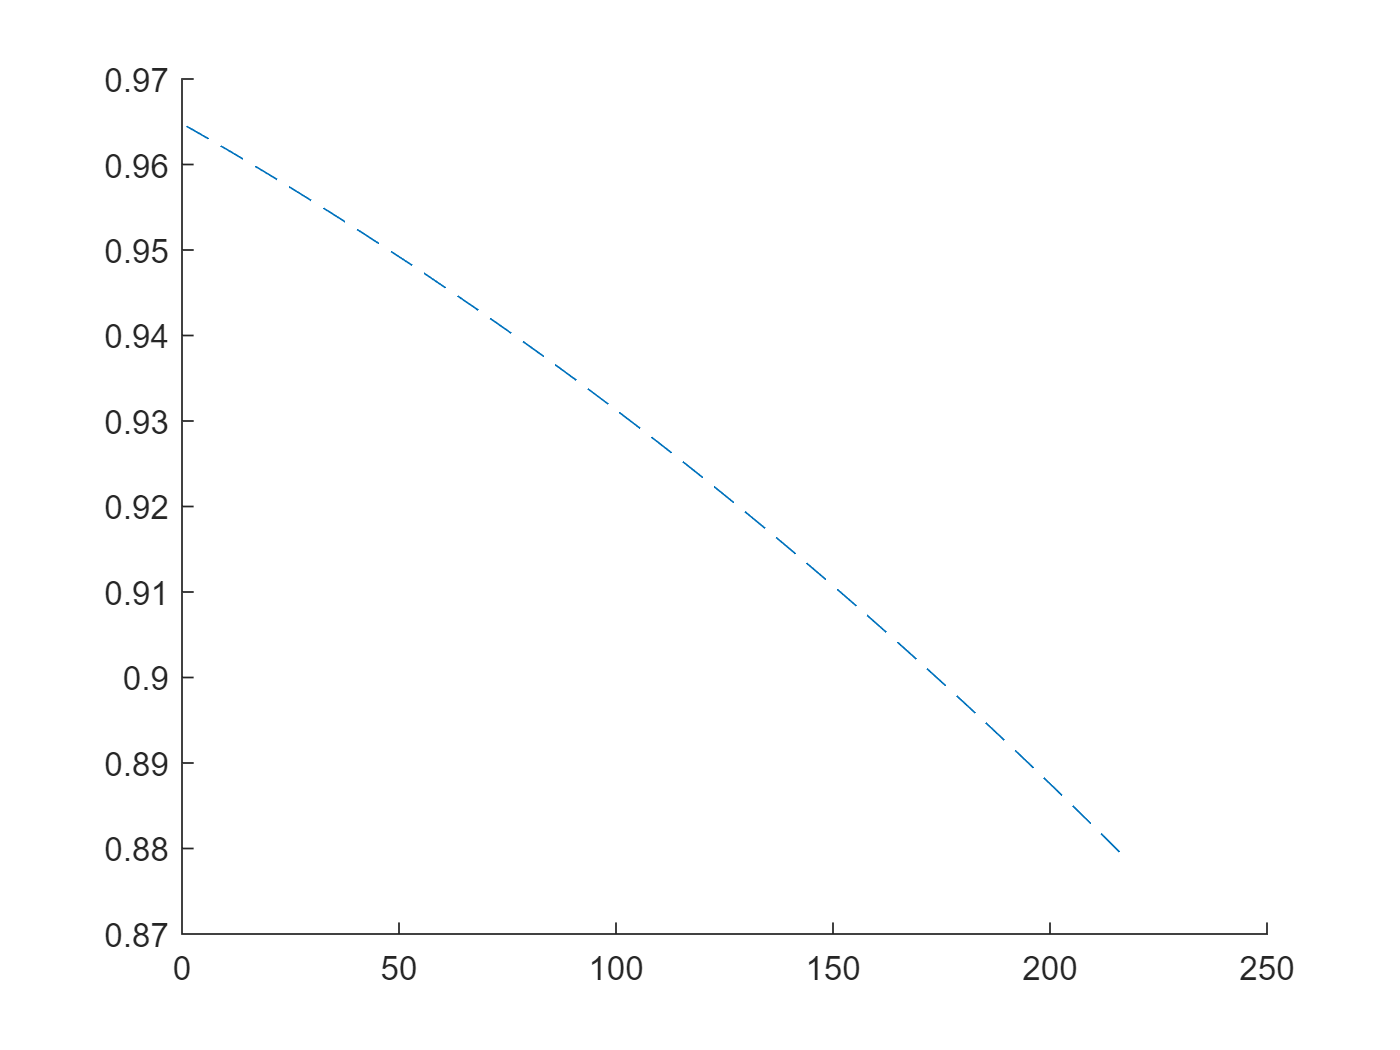


figure, hold on
plot(Y_test_RUL_idx1_bat16(idxCross:end))
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth(idxCrossSel:end),'--')
hold off

%{
% for scenario 5a, find best/2nd fit training data = find similar at middle
% point 


for i=1:idxAll
end

compareTo = rul_data(idx_after_change); %Y_test_RUL_ref(idx_after_change);

% find most similar data
% idxTrainValid = [idxTrain idxValid]

count = length(idxTrain) + length(idxValid);
idxSel = 0;
idxSel_2nd = 0;
idxCrossSel = 0;
diff = 1000;
for i=1:count 
    [val,idxCross] = min(abs(ryan4_battery_dataset(idxTrainValid(i)).QDischarge -  idx2halfChangeCap ));
    rul_remained =  ryan4_battery_dataset(idxTrainValid(i)).cycle_life - idxCross ;
    diff_new = abs( rul_remained - compareTo );
    if diff_new < diff 
        idxSel_2nd = idxSel;
        idxCrossSel_2nd = idxCrossSel;
        idxSel = idxTrainValid(i);
        diff = diff_new;
        idxCrossSel = idxCross;
    end
end

matchedRUL = ryan4_battery_dataset(idxSel).cycle_life - idxCrossSel;
inTrain = any(idxTrain==idxSel);
inValid = any(idxValid==idxSel);
matchedRUL_2nd = ryan4_battery_dataset(idxSel_2nd).cycle_life - idxCrossSel_2nd;
inTrain_2nd = any(idxTrain==idxSel_2nd);
inValid_2nd = any(idxValid==idxSel_2nd);

%}


%{
idx2halfChange = 1
idx2halfChangeCap = ryan4_change_21Qd(1)
ryan4_battery_dataset(batNum_ref).cycle_life

ryan4_change_21Qd
[ref_bat_index, ref_bat_rul,ref_bat_cross,ref_bat_index_2nd, ref_bat_rul_2nd,ref_bat_cross_2nd ] = ...
    ryan4_util_find_similar_bat_with_rul_after_change( ryan4_change_21RulOrg,1, idx2halfChangeCap)

%}

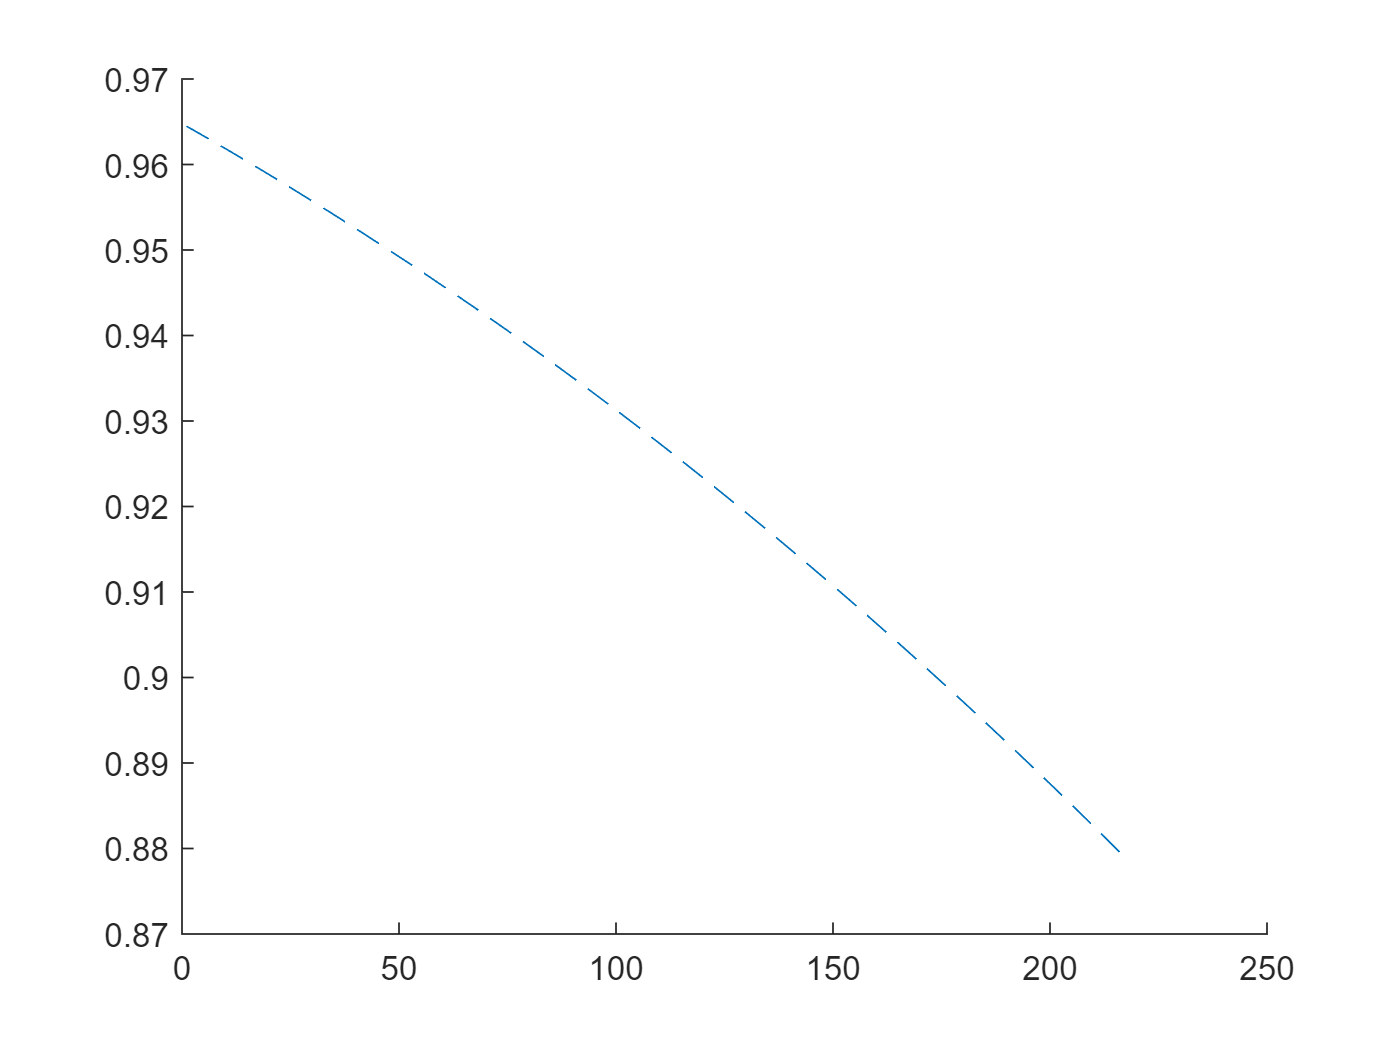


figure, hold on
plot(Y_test_RUL_idx1_bat16(idxCross:end))
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth(idxCrossSel:end),'--')
hold off

ryan4_data_global
% Cap_change = (Cap_Rated + Cap_EOL ) / 2

[ref_bat_index, ref_bat_rul,ref_bat_cross,ref_bat_index_2nd, ref_bat_rul_2nd,ref_bat_cross_2nd ] = ...
    ryan4_util_find_similar_bat_with_rul_after_change( ryan4_change_21RulOrg,idx2change+1, Cap_change)

ref_bat_index = 61

ref_bat_rul = 44

ref_bat_cross = 102

ref_bat_index_2nd = 39

ref_bat_rul_2nd = 43

ref_bat_cross_2nd = 141

ref_bat_index_2nd

ref_bat_index_2nd = 39



% batNum_ref = idxAll(ref_bat_index)
% batNum_ref_2nd = idxAll(ref_bat_index_2nd)
batNum_ref = (ref_bat_index)

batNum_ref = 61

batNum_ref_2nd = (ref_bat_index_2nd)

batNum_ref_2nd = 39




ref_bat_index

ref_bat_index = 61

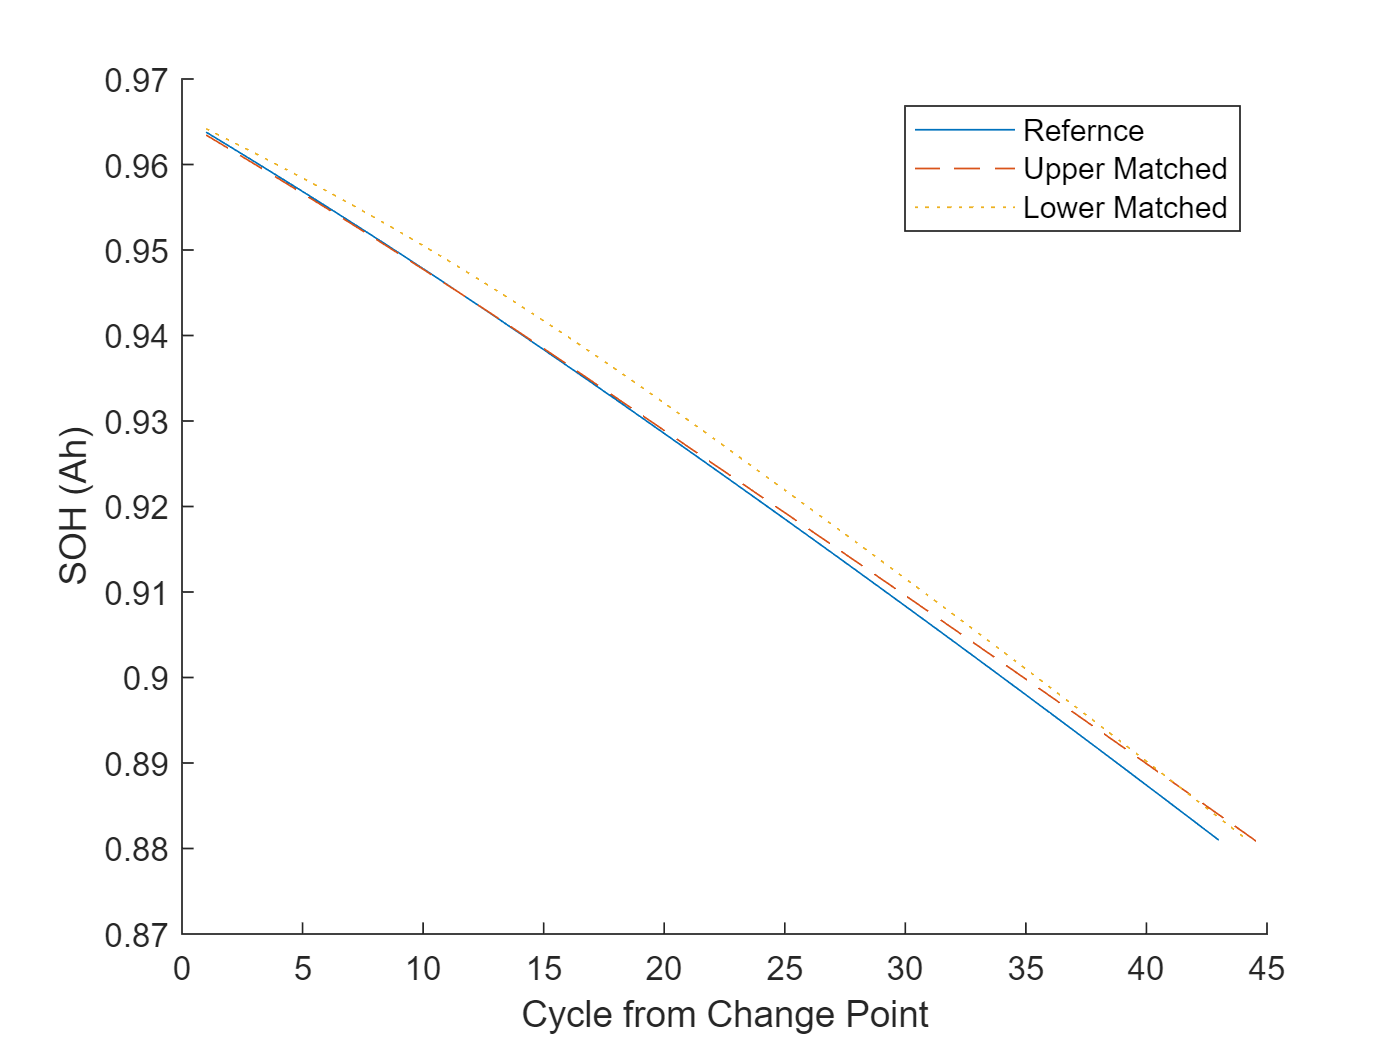




figure, hold on
plot(ryan4_change_21Qd(idx2change+1:end))
plot(ryan4_battery_dataset(batNum_ref).QDischargeSmooth(ref_bat_cross:end),'--')
plot(ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(ref_bat_cross_2nd:end),':')
ylabel('SOH (Ah)')
xlabel('Cycle from Change Point')
hold off
legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'Upper Matched';
legend_str{3} = 'Lower Matched';
legend(legend_str)


%[ref_bat_index, ref_bat_rul,ref_bat_cross,ref_bat_index_2nd, ref_bat_rul_2nd,ref_bat_cross_2nd ] = ...
%    ryan4_util_find_similar_bat_with_rul_after_change( ryan4_change_21RulOrg,idx2change+1, Cap_change)

% batNum_ref = idxAll(ref_bat_index)
% batNum_ref_2nd = idxAll(ref_bat_index_2nd)

% batNum_ref = ref_bat_index
% batNum_ref_2nd = ref_bat_index_2nd

ref_bat_cross

ref_bat_cross = 102

ref_bat_cross_2nd

ref_bat_cross_2nd = 141

figure, hold on
plot(ryan4_change_21Qd(idx2change+1:end))
plot(ryan4_battery_dataset(batNum_ref).QDischargeSmooth(ref_bat_cross:end),'--')
plot(ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(ref_bat_cross_2nd:end),':')
ylabel('SOH (Ah)')
xlabel('Cycle from Change Point')
hold off
legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'Upper Matched';
legend_str{3} = 'Lower Matched';
legend(legend_str)

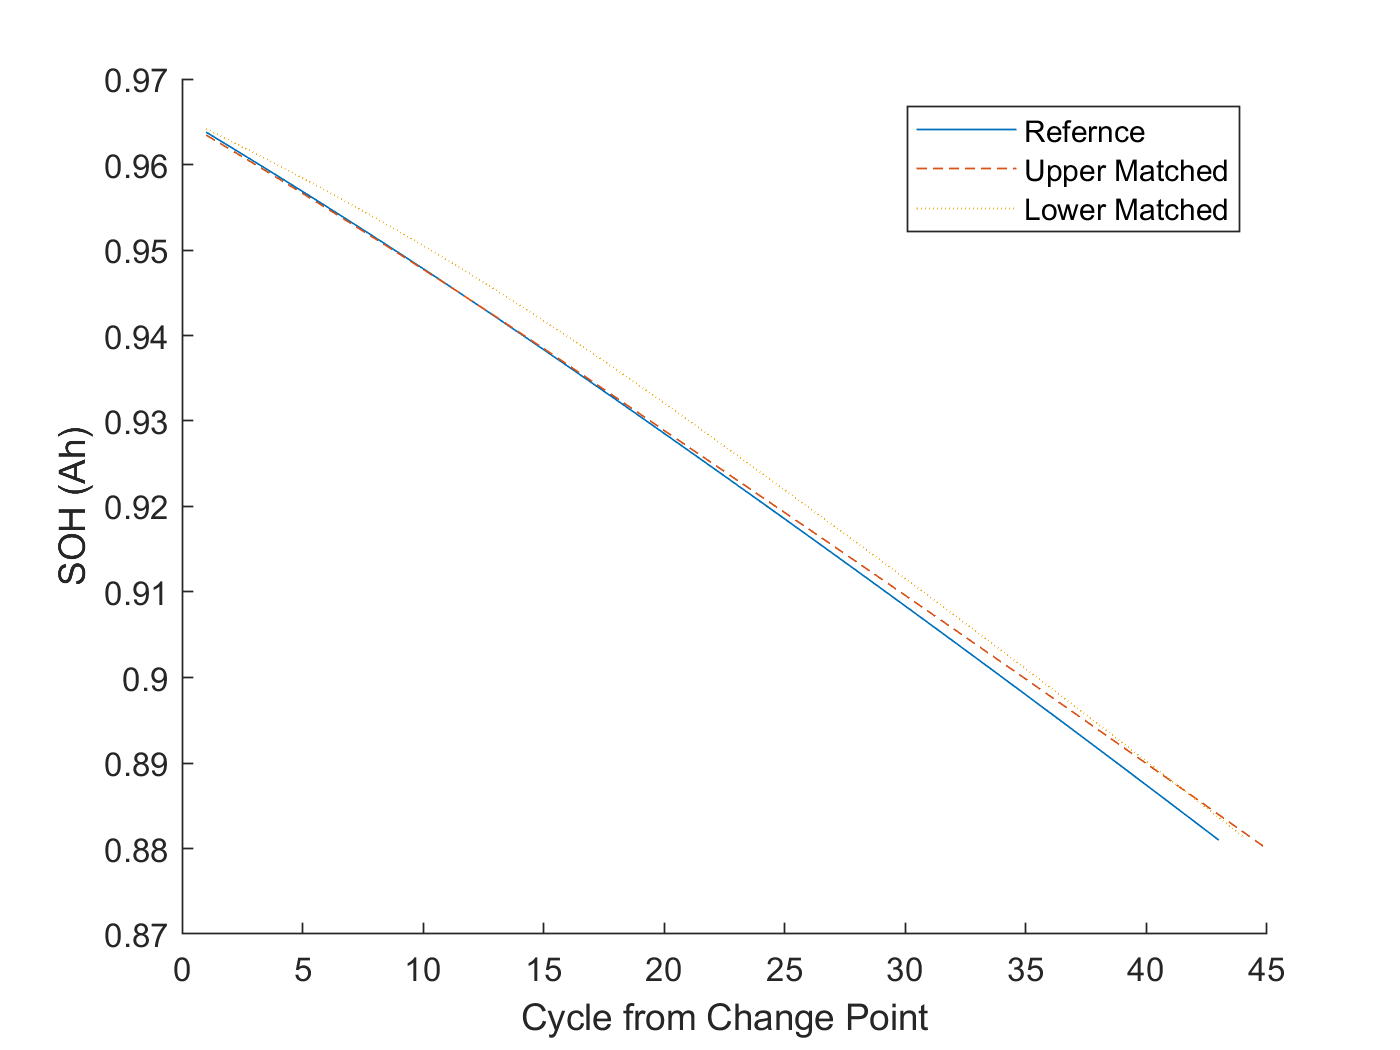


figure, hold on
plot(ryan4_change_21Qd(idx2change+1:end))
plot(ryan4_battery_dataset(batNum_ref).QDischargeSmooth(ref_bat_cross:end),'--')
plot(ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(ref_bat_cross_2nd:end),':')
hold off
ylabel('SOH (Ah)')
xlabel('Cycle from Change Point')

legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'Upper Matched';
legend_str{3} = 'Lower Matched';
legend(legend_str)



%test_data_2_bast_match_SOH_post = [ryan4_battery_dataset(batNum_ref).QDischargeSmooth(ref_bat_cross:end)];
%test_data_2_2nd_match_SOH_post = [ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(ref_bat_cross_2nd:end)];

scenario_7_test_data_2_bestMatch_SOH_post= ryan4_battery_dataset(batNum_ref).QDischargeSmooth(ref_bat_cross:end);
scenario_7_test_data_2_2ndMatch_SOH_post  = ryan4_battery_dataset(batNum_ref_2nd).QDischargeSmooth(ref_bat_cross_2nd:end);

scenario_7_test_data_2_bestMatch_SOH = [ scenario_7_test_data_2_bestMatch_SOH_pre ; scenario_7_test_data_2_bestMatch_SOH_post];
scenario_7_test_data_2_2ndMatch_SOH = [ scenario_7_test_data_2_2ndMatch_SOH_pre ; scenario_7_test_data_2_2ndMatch_SOH_post];

scenario_7_test_data_2_base_SOH = ryan4_change_21Qd;
scenario_7_test_data_2_base_RUL = ryan4_change_21RulOrg;

scenario_7_test_data_2_bestMatch_RUL_post = linspace(length(scenario_7_test_data_2_bestMatch_SOH_post), ...
     1 , length(scenario_7_test_data_2_bestMatch_SOH_post))

scenario_7_test_data_2_bestMatch_RUL_post =     45    44    43    42    41    40    39    38    37    36    35    34    33    32    31    30    29    28    27    26    25    24    23    22    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1



scenario_7_test_data_2_2ndMatch_RUL_post = linspace(length(scenario_7_test_data_2_2ndMatch_SOH_post), ...
     1 , length(scenario_7_test_data_2_2ndMatch_SOH_post))

scenario_7_test_data_2_2ndMatch_RUL_post =     44    43    42    41    40    39    38    37    36    35    34    33    32    31    30    29    28    27    26    25    24    23    22    21    20    19    18    17    16    15    14    13    12    11    10     9     8     7     6     5     4     3     2     1


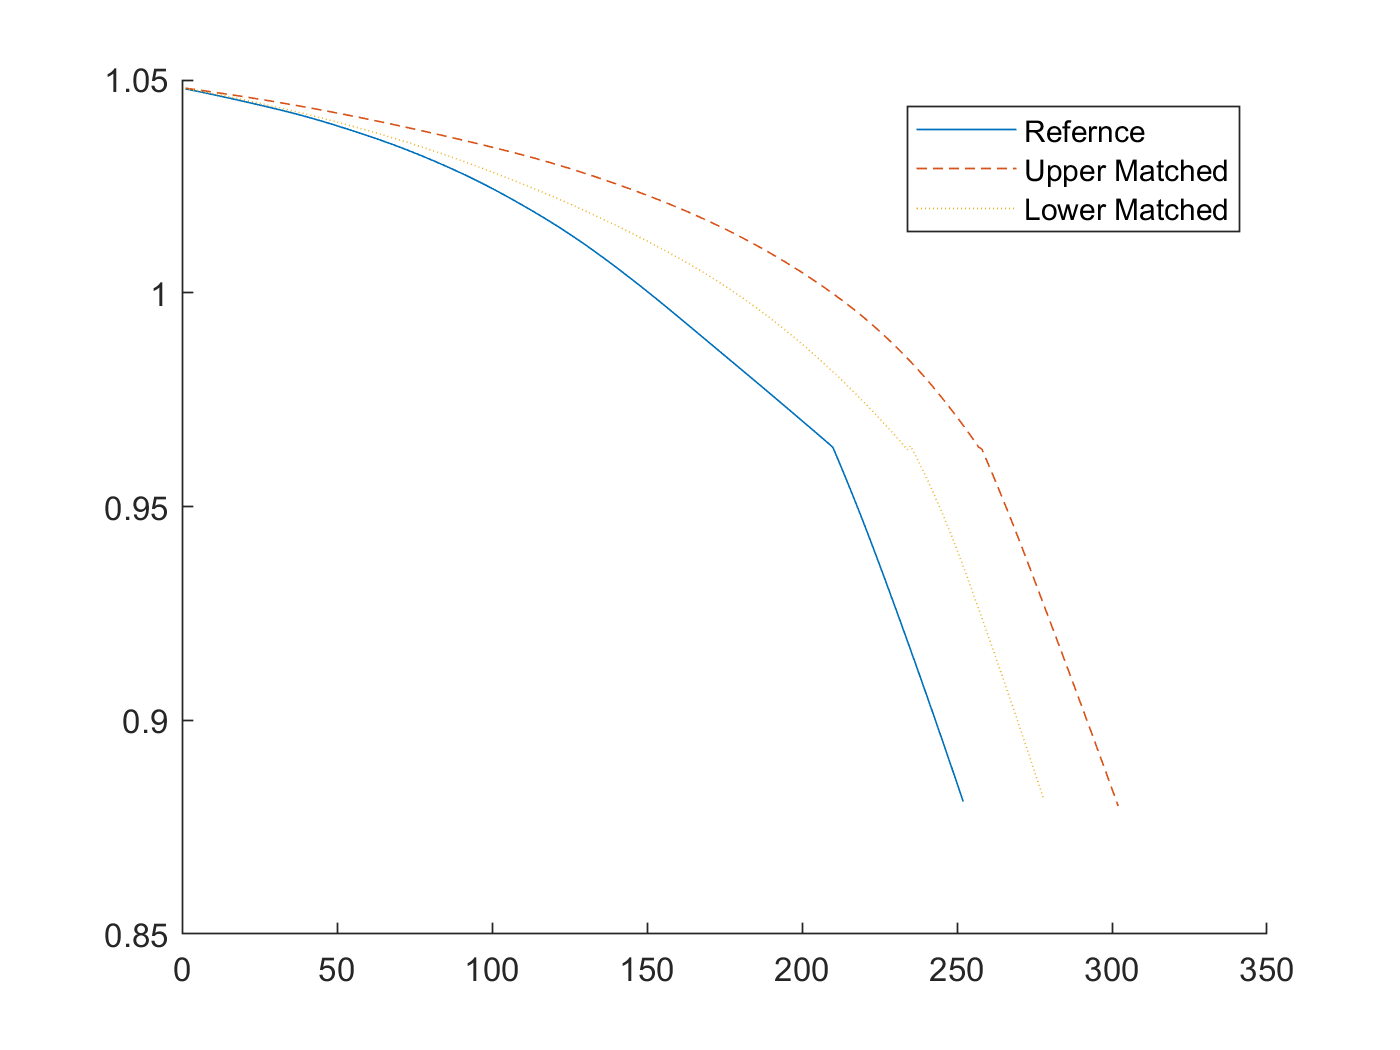


scenario_7_test_data_2_bestMatch_RUL = [ scenario_7_test_data_2_bestMatch_RUL_pre  scenario_7_test_data_2_bestMatch_RUL_post ]';
scenario_7_test_data_2_2ndMatch_RUL = [ scenario_7_test_data_2_2ndMatch_RUL_pre  scenario_7_test_data_2_2ndMatch_RUL_post]';

figure, hold on
plot(scenario_7_test_data_2_base_SOH)
plot(scenario_7_test_data_2_bestMatch_SOH,'--')
plot(scenario_7_test_data_2_2ndMatch_SOH,':')
hold off
legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'Upper Matched';
legend_str{3} = 'Lower Matched';
legend(legend_str)

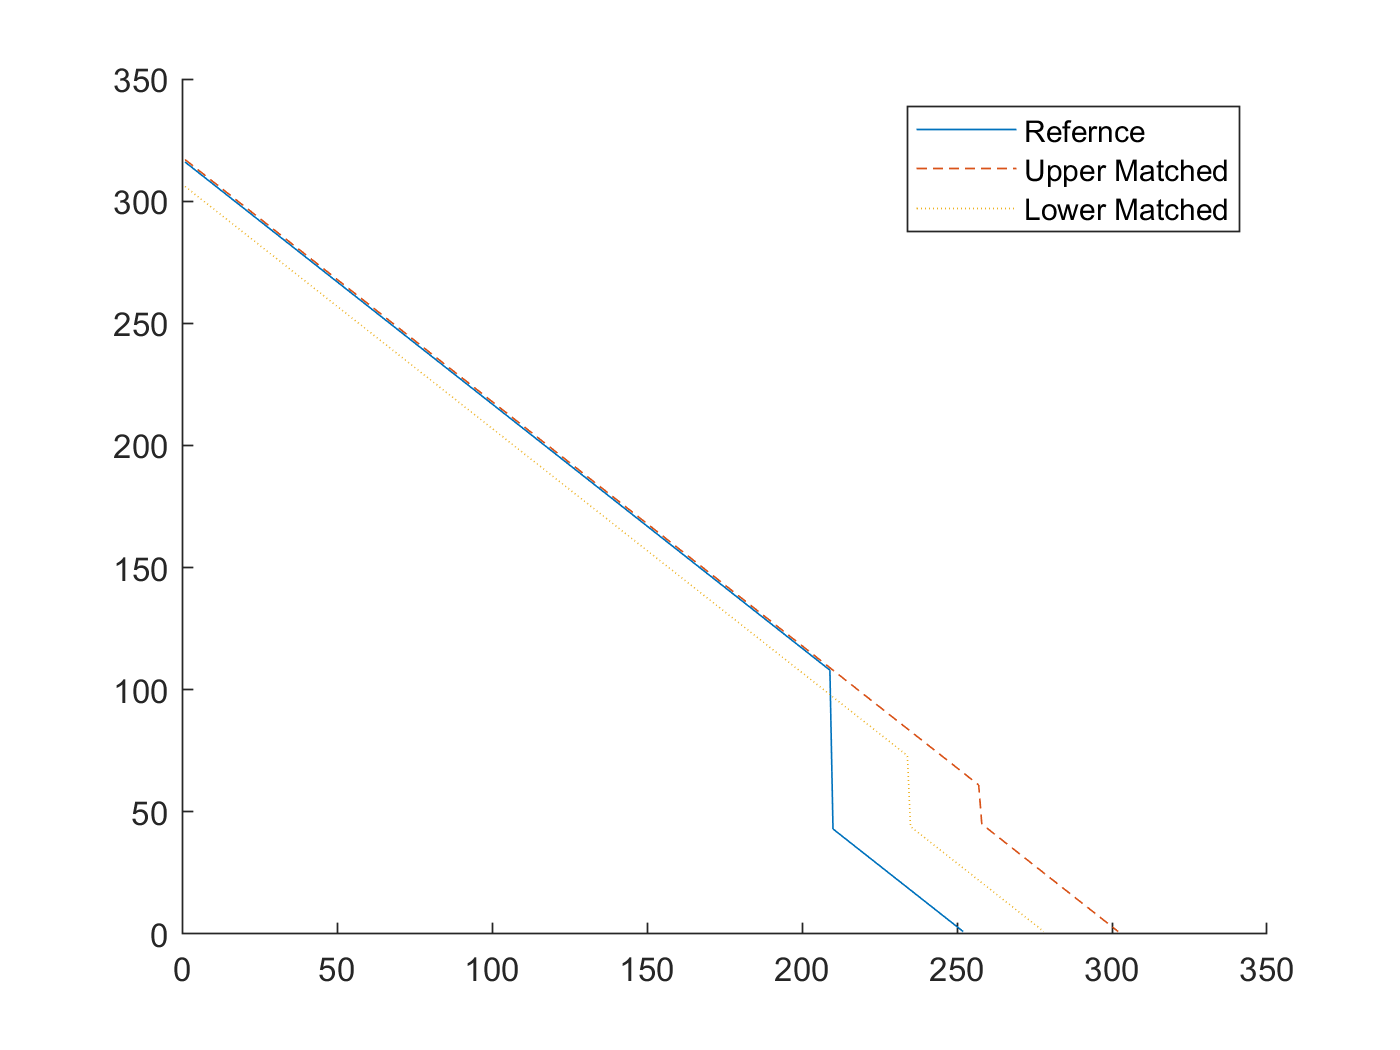


figure, hold on
plot(scenario_7_test_data_2_base_RUL)
plot(scenario_7_test_data_2_bestMatch_RUL,'--')
plot(scenario_7_test_data_2_2ndMatch_RUL,':')
hold off
legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'Upper Matched';
legend_str{3} = 'Lower Matched';
legend(legend_str)

%%%%%%%%%%%%%%%%


idxTest

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxTest(1)

ans = 76

idxTest(7)

ans = 16

idxTest(10)

ans = 106

%%%%%%%%%%%
idxTestBatSmall = 7;
idxTestBatNumSmall = idxTestSort(idxTestBatSmall)

idxTestBatNumSmall = 76

idxTestBatRef = 1;
idxTestBatNumRef = idxTestSort(idxTestBatRef)

idxTestBatNumRef = 16

idxTestBatBig = 11;
idxTestBatNumBig = idxTestSort(idxTestBatBig)

idxTestBatNumBig = 106

ynorm_ryan4_change_21Rul = minmax_norm_x_with_param(ryan4_change_21Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_21Rul =     0.2145
    0.2137
    0.2128
    0.2120
    0.2111
    0.2103
    0.2094
    0.2085
    0.2077
    0.2068


ynorm_ryan4_change_22Rul = minmax_norm_x_with_param(ryan4_change_22Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_22Rul =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_ryan4_change_23Rul = minmax_norm_x_with_param(ryan4_change_23Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_23Rul =     0.3171
    0.3162
    0.3154
    0.3145
    0.3137
    0.3128
    0.3120
    0.3111
    0.3103
    0.3094


ynorm_ryan4_change_21Qd  = minmax_norm_x_with_param(ryan4_change_21Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_21Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


ynorm_ryan4_change_22Qd  = minmax_norm_x_with_param(ryan4_change_22Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_22Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


ynorm_ryan4_change_23Qd  = minmax_norm_x_with_param(ryan4_change_23Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_23Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


xnorm_ryan4_change_21Vd  = minmax_norm_x_with_param(ryan4_change_21Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_21Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209

xnorm_ryan4_change_22Vd  = minmax_norm_x_with_param(ryan4_change_22Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_22Vd = 316×20
    0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194   

xnorm_ryan4_change_23Vd  = minmax_norm_x_with_param(ryan4_change_23Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_23Vd = 372×20
    0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194   


ynorm_ryan4_change_21RulOrg = minmax_norm_x_with_param(ryan4_change_21RulOrg  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_21RulOrg = 252×1
    0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_ryan4_change_23RulOrg = minmax_norm_x_with_param(ryan4_change_23RulOrg  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_23RulOrg = 372×1
    0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_scenario_7_test_data_2_base_RUL = minmax_norm_x_with_param(scenario_7_test_data_2_base_RUL  , ymin_RUL , yrate_RUL )

ynorm_scenario_7_test_data_2_base_RUL = 252×1
    0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_scenario_7_test_data_2_bestMatch_RUL = minmax_norm_x_with_param(scenario_7_test_data_2_bestMatch_RUL  , ymin_RUL , yrate_RUL )

ynorm_scenario_7_test_data_2_bestMatch_RUL = 302×1
    0.2701
    0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624


ynorm_scenario_7_test_data_2_2ndMatch_RUL = minmax_norm_x_with_param(scenario_7_test_data_2_2ndMatch_RUL  , ymin_RUL , yrate_RUL )

ynorm_scenario_7_test_data_2_2ndMatch_RUL = 278×1
    0.2607
    0.2598
    0.2590
    0.2581
    0.2573
    0.2564
    0.2556
    0.2547
    0.2538
    0.2530



xnorm_ref   = xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatRef ))) , : );
xnorm_small = xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatSmall ))) , : );
xnorm_big = xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatBig ))) , : );

ynorm_ref   = ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatRef ))) , : );
ynorm_small = ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatSmall ))) , : );
ynorm_big = ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatBig ))) , : );

Y_ref   = RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatRef ))) , : );
Y_small = RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatSmall ))) , : );
Y_big = RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatBig ))) , : );

xnorm_ref_to_small   = xnorm_ryan4_change_21Vd;
xnorm_ref_to_big     = xnorm_ryan4_change_23Vd;
xnorm_ref_to_small2   = xnorm_ref_to_small;
xnorm_ref_to_big2     = xnorm_ref_to_big;

ynorm_ref_to_small   = ynorm_ryan4_change_21Rul;
ynorm_ref_to_big     = ynorm_ryan4_change_23Rul;
size(ynorm_ryan4_change_23Rul)

ans = 1×2
   372     1


size(ynorm_ref_to_big)

ans = 1×2
   372     1



ynorm_ref_to_small2   = ynorm_ryan4_change_21RulOrg;
ynorm_ref_to_big2     = ynorm_ryan4_change_23RulOrg;

Y_ref_to_small   = ryan4_change_21Rul;
Y_ref_to_big     = ryan4_change_23Rul;
Y_ref_to_small2   = ryan4_change_21RulOrg;
Y_ref_to_big2     = ryan4_change_23RulOrg;

%%
Y_soh_ref   = Cap( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatRef ))) , : );
Y_soh_small = Cap( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatSmall ))) , : );
Y_soh_big   = Cap( idxTestAll(find(idxTestAll_batIndex == idxTestSort(idxTestBatBig ))) , : );

ynorm_soh_ref_to_small2   = ynorm_ryan4_change_21Qd;
ynorm_soh_ref_to_big2     = ynorm_ryan4_change_23Qd;
Y_soh_ref_to_small2   = ryan4_change_21Qd;
Y_soh_ref_to_big2     = ryan4_change_23Qd;
%%

len_ref            =  length(xnorm_ref            ) - mod(length(xnorm_ref          ),5) ; 
len_small          =  length(xnorm_small           ) - mod(length(xnorm_small       ),5) ; 
len_big            =  length(xnorm_big             ) - mod(length(xnorm_big          ),5) ; 
len_ref_to_small   =  length(xnorm_ref_to_small    ) - mod(length(xnorm_ref_to_small ),5) ; 
len_ref_to_big     =  length(xnorm_ref_to_big      ) - mod(length(xnorm_ref_to_big   ),5) ; 
len_ref_to_small2   =  length(xnorm_ref_to_small2  ) - mod(length(xnorm_ref_to_small2),5) ;
len_ref_to_big2     =  length(xnorm_ref_to_big2   ) - mod(length(xnorm_ref_to_big2 ),5) ; 

xnorm_ref            =  xnorm_ref           (1:len_ref                 ,:     ) ; 
xnorm_small          =  xnorm_small         (1:len_small               ,:     ) ; 
xnorm_big            =  xnorm_big           (1:len_big                 ,:     ) ; 
xnorm_ref_to_small   =  xnorm_ref_to_small  (1:len_ref_to_small        ,:     ) ; 
xnorm_ref_to_big     =  xnorm_ref_to_big    (1:len_ref_to_big          ,:     ) ; 
xnorm_ref_to_small2   =  xnorm_ref_to_small2  (1:len_ref_to_small2     ,:        ) ; 
xnorm_ref_to_big2     =  xnorm_ref_to_big2    (1:len_ref_to_big2       ,:        ) ; 


size(ynorm_ref_to_big)

ans = 1×2
   372     1


ynorm_ref            =  ynorm_ref           (1:len_ref                      ) ; 
ynorm_small          =  ynorm_small         (1:len_small                    ) ; 
ynorm_big            =  ynorm_big           (1:len_big                      ) ; 
ynorm_ref_to_small   =  ynorm_ref_to_small  (1:len_ref_to_small             ) ; 
ynorm_ref_to_big     =  ynorm_ref_to_big    (1:len_ref_to_big               ) ; 
ynorm_ref_to_small2   =  ynorm_ref_to_small2  (1:len_ref_to_small2             ) ; 
ynorm_ref_to_big2     =  ynorm_ref_to_big2    (1:len_ref_to_big2               ) ; 
ynorm_soh_ref_to_small2   =  ynorm_soh_ref_to_small2  (1:len_ref_to_small2             ) ; 
ynorm_soh_ref_to_big2     =  ynorm_soh_ref_to_big2    (1:len_ref_to_big2               ) ; 

Y_ref            =  Y_ref           (1:len_ref                      ) ; 
Y_small          =  Y_small         (1:len_small                    ) ; 
Y_big            =  Y_big           (1:len_big                      ) ; 
Y_ref_to_small   =  Y_ref_to_small  (1:len_ref_to_small             ) ; 
Y_ref_to_big     =  Y_ref_to_big    (1:len_ref_to_big               ) ; 
Y_ref_to_small2   =  Y_ref_to_small2  (1:len_ref_to_small2             ) ; 
Y_ref_to_big2     =  Y_ref_to_big2    (1:len_ref_to_big2               ) ; 

%%
Y_soh_ref            =  Y_soh_ref           (1:len_ref                      ) ; 
Y_soh_small          =  Y_soh_small         (1:len_small                    ) ; 
Y_soh_big            =  Y_soh_big           (1:len_big                      ) ; 
Y_soh_ref_to_small2   =  Y_soh_ref_to_small2  (1:len_ref_to_small2             ) ; 
Y_soh_ref_to_big2     =  Y_soh_ref_to_big2    (1:len_ref_to_big2               ) ; 



xnorm_1  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) , : );
xnorm_2  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(2 ))) , : );
xnorm_3  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(3 ))) , : );
xnorm_4  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(4 ))) , : );
xnorm_5  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(5 ))) , : );
xnorm_6  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(6 ))) , : );
xnorm_7  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(7 ))) , : );
xnorm_8  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(8 ))) , : );
xnorm_9  =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(9 ))) , : );
xnorm_10 =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(10))) , : );
xnorm_11 =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(11))) , : );
xnorm_12 =  xnorm_Vd( idxTestAll(find(idxTestAll_batIndex == idxTestSort(12))) , : );

ynorm_1  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) );
ynorm_2  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(2 ))) );
ynorm_3  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(3 ))) );
ynorm_4  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(4 ))) );
ynorm_5  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(5 ))) );
ynorm_6  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(6 ))) );
ynorm_7  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(7 ))) );
ynorm_8  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(8 ))) );
ynorm_9  =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(9 ))) );
ynorm_10 =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(10))) );
ynorm_11 =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(11))) );
ynorm_12 =  ynorm_RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(12))) );

Y_1  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(1 ))) );
Y_2  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(2 ))) );
Y_3  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(3 ))) );
Y_4  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(4 ))) );
Y_5  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(5 ))) );
Y_6  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(6 ))) );
Y_7  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(7 ))) );
Y_8  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(8 ))) );
Y_9  =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(9 ))) );
Y_10 =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(10))) );
Y_11 =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(11))) );
Y_12 =  RUL( idxTestAll(find(idxTestAll_batIndex == idxTestSort(12))) );
	

len_1  =  length(xnorm_1 ) - mod(length(xnorm_1 ),5) ; 
len_2  =  length(xnorm_2 ) - mod(length(xnorm_2 ),5) ; 
len_3  =  length(xnorm_3 ) - mod(length(xnorm_3 ),5) ; 
len_4  =  length(xnorm_4 ) - mod(length(xnorm_4 ),5) ; 
len_5  =  length(xnorm_5 ) - mod(length(xnorm_5 ),5) ; 
len_6  =  length(xnorm_6 ) - mod(length(xnorm_6 ),5) ; 
len_7  =  length(xnorm_7 ) - mod(length(xnorm_7 ),5) ; 
len_8  =  length(xnorm_8 ) - mod(length(xnorm_8 ),5) ; 
len_9  =  length(xnorm_9 ) - mod(length(xnorm_9 ),5) ; 
len_10 =  length(xnorm_10) - mod(length(xnorm_10),5) ; 
len_11 =  length(xnorm_11) - mod(length(xnorm_11),5) ; 
len_12 =  length(xnorm_12) - mod(length(xnorm_12),5) ; 


xnorm_1  =  xnorm_1 (1:len_1  ,:);
xnorm_2  =  xnorm_2 (1:len_2  ,:);
xnorm_3  =  xnorm_3 (1:len_3  ,:);
xnorm_4  =  xnorm_4 (1:len_4  ,:);
xnorm_5  =  xnorm_5 (1:len_5  ,:);
xnorm_6  =  xnorm_6 (1:len_6  ,:);
xnorm_7  =  xnorm_7 (1:len_7  ,:);
xnorm_8  =  xnorm_8 (1:len_8  ,:);
xnorm_9  =  xnorm_9 (1:len_9  ,:);
xnorm_10 =  xnorm_10(1:len_10 ,:);
xnorm_11 =  xnorm_11(1:len_11 ,:);
xnorm_12 =  xnorm_12(1:len_12 ,:);

ynorm_1  =  ynorm_1 (1:len_1  ,:);
ynorm_2  =  ynorm_2 (1:len_2  ,:);
ynorm_3  =  ynorm_3 (1:len_3  ,:);
ynorm_4  =  ynorm_4 (1:len_4  ,:);
ynorm_5  =  ynorm_5 (1:len_5  ,:);
ynorm_6  =  ynorm_6 (1:len_6  ,:);
ynorm_7  =  ynorm_7 (1:len_7  ,:);
ynorm_8  =  ynorm_8 (1:len_8  ,:);
ynorm_9  =  ynorm_9 (1:len_9  ,:);
ynorm_10 =  ynorm_10(1:len_10 ,:);
ynorm_11 =  ynorm_11(1:len_11 ,:);
ynorm_12 =  ynorm_12(1:len_12 ,:);

Y_1  =  Y_1 (1:len_1  ,:);
Y_2  =  Y_2 (1:len_2  ,:);
Y_3  =  Y_3 (1:len_3  ,:);
Y_4  =  Y_4 (1:len_4  ,:);
Y_5  =  Y_5 (1:len_5  ,:);
Y_6  =  Y_6 (1:len_6  ,:);
Y_7  =  Y_7 (1:len_7  ,:);
Y_8  =  Y_8 (1:len_8  ,:);
Y_9  =  Y_9 (1:len_9  ,:);
Y_10 =  Y_10(1:len_10 ,:);
Y_11 =  Y_11(1:len_11 ,:);
Y_12 =  Y_12(1:len_12 ,:);

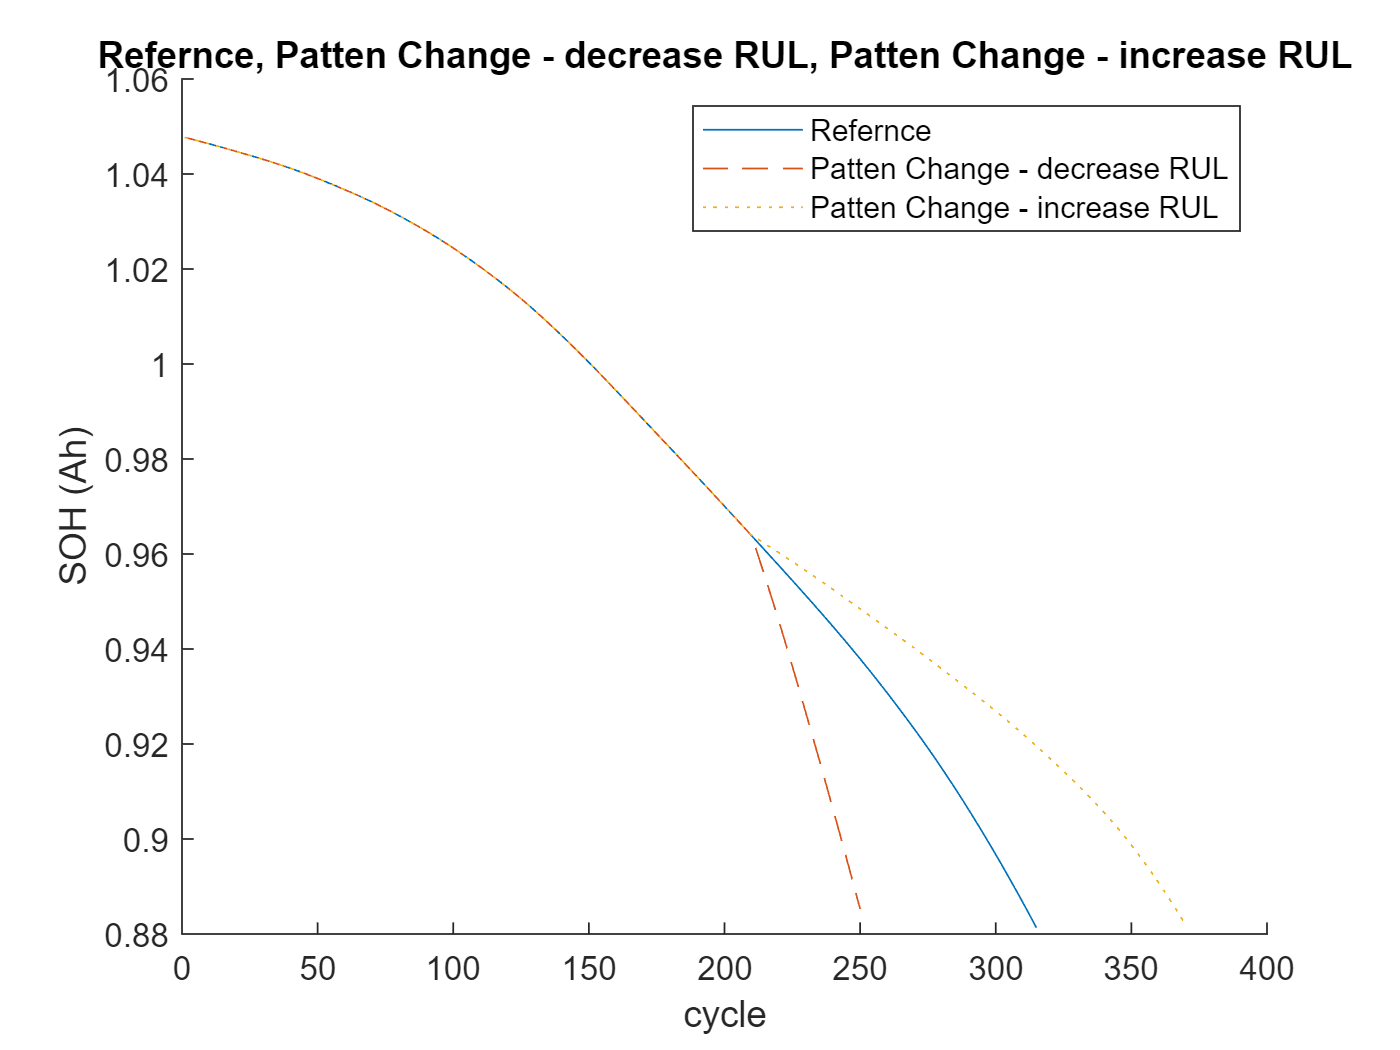



figure
hold on 
plot(Y_soh_ref)
plot(Y_soh_ref_to_small2,'--')
plot(Y_soh_ref_to_big2,':')
hold off
title 'Refernce, Patten Change - decrease RUL, Patten Change - increase RUL'
ylabel('SOH (Ah)')
xlabel('cycle')
legend_str = cell(3,1);
legend_str{1} = 'Refernce';
legend_str{2} = 'Patten Change - decrease RUL';
legend_str{3} = 'Patten Change - increase RUL';
legend(legend_str)

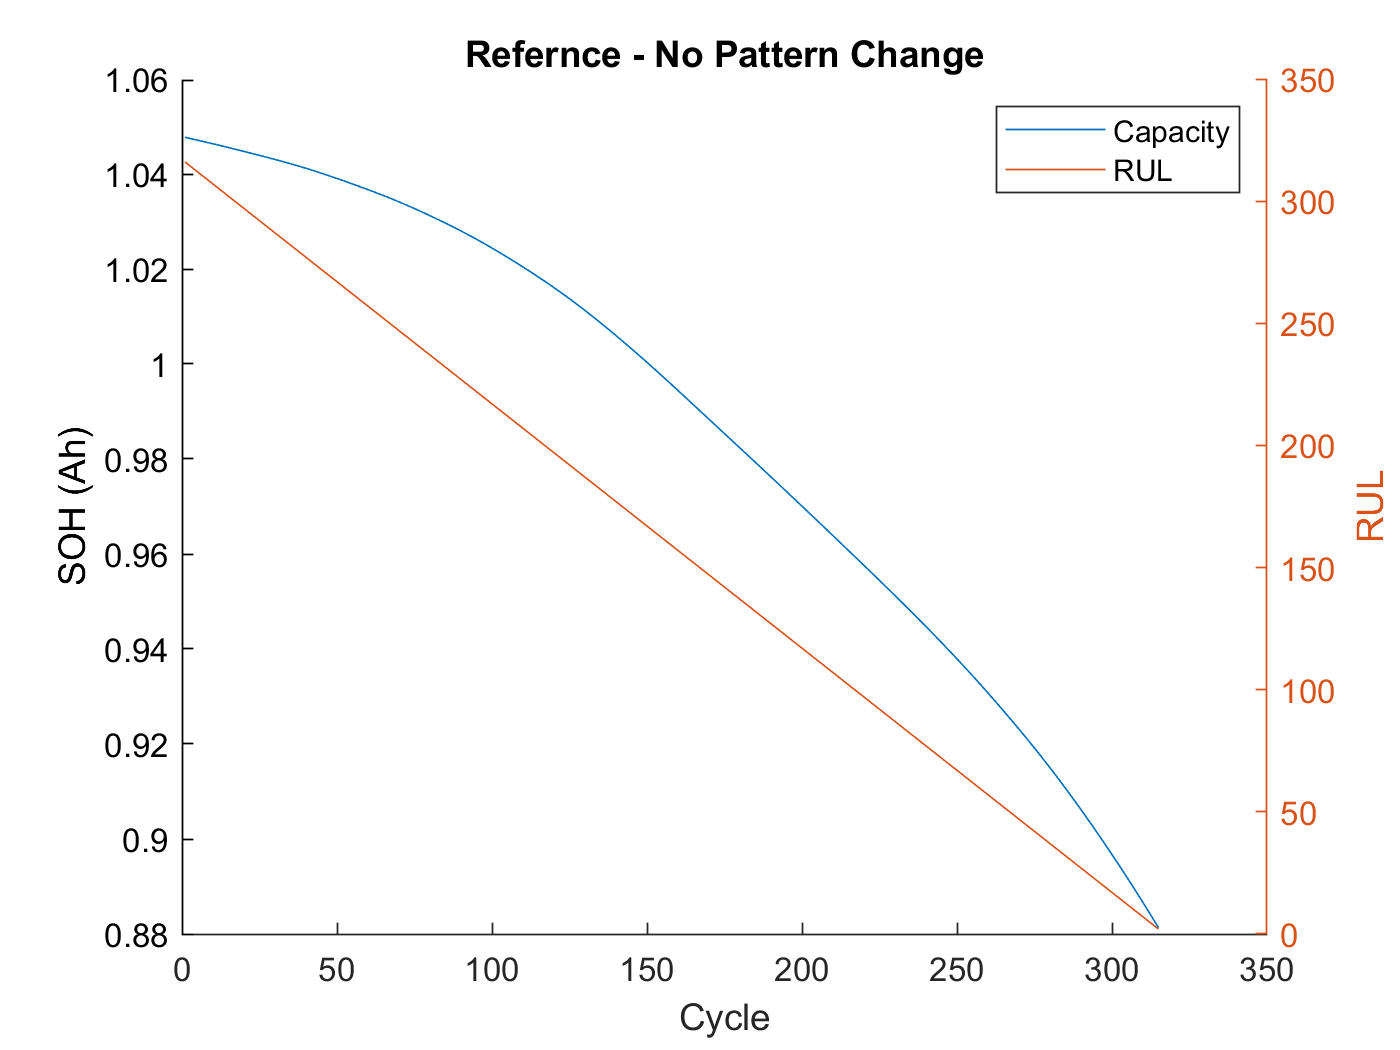

figure
hold on 
plot(Y_soh_ref)
ylabel('SOH (Ah)')
yyaxis right
ylabel('RUL')
plot(Y_ref)
hold off
xlabel('Cycle')
title('Refernce - No Pattern Change')
legend_str = cell(2,1);
legend_str{1} = 'Capacity';
legend_str{2} = 'RUL';
legend(legend_str)

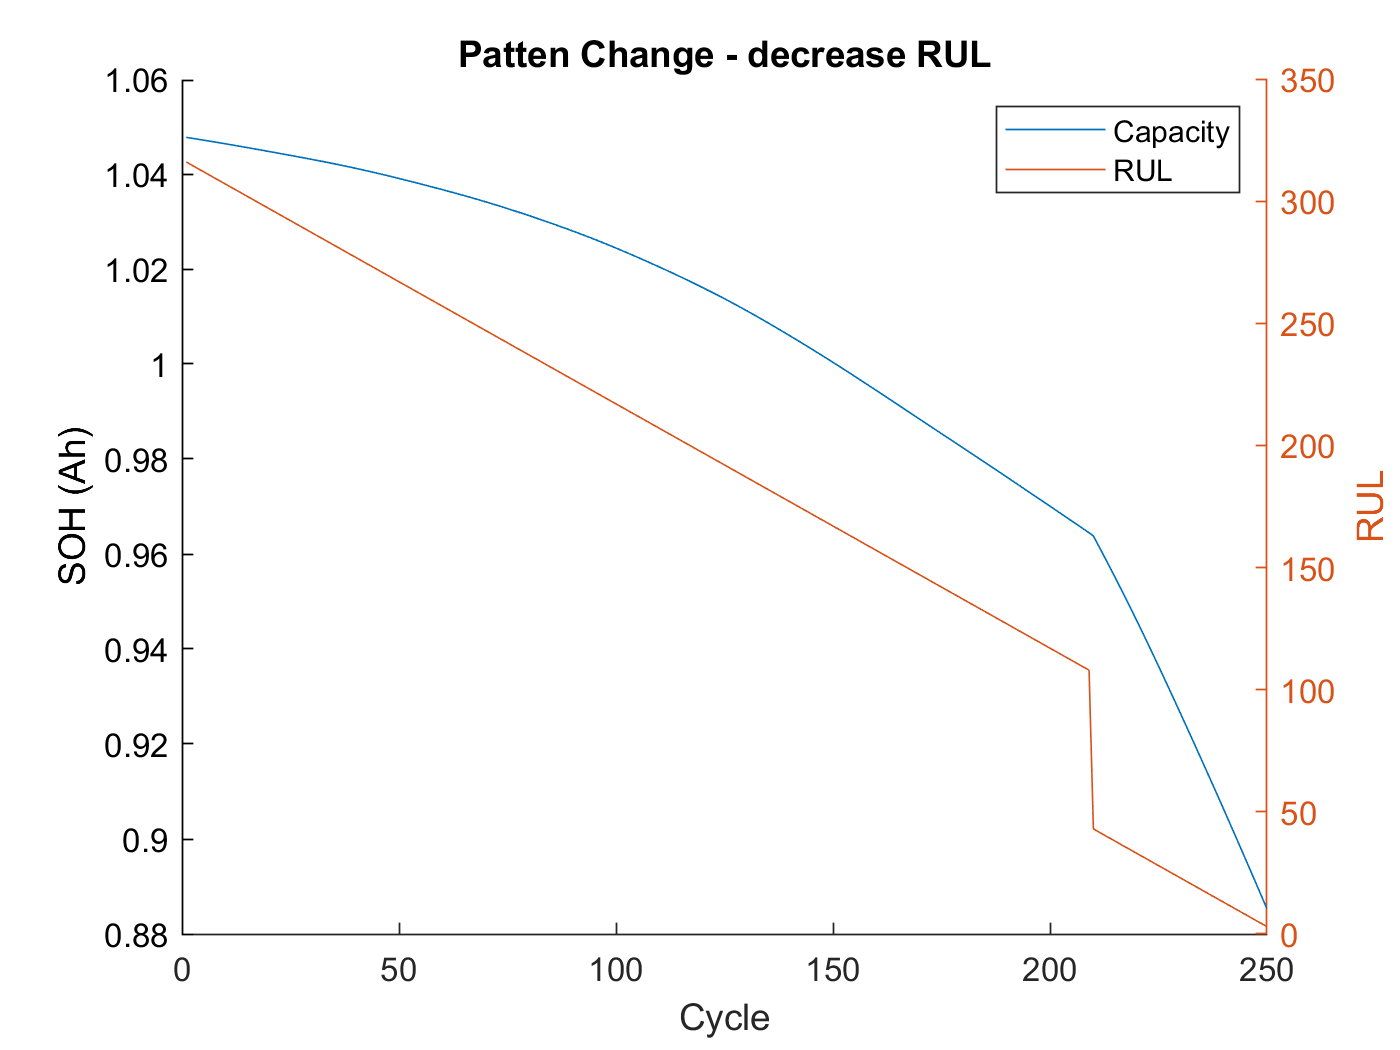

figure
hold on 
plot(Y_soh_ref_to_small2)
ylabel('SOH (Ah)')
yyaxis right
ylabel('RUL')
plot(Y_ref_to_small2)
hold off
xlabel('Cycle')
title('Patten Change - decrease RUL')
legend_str = cell(2,1);
legend_str{1} = 'Capacity';
legend_str{2} = 'RUL';
legend(legend_str)

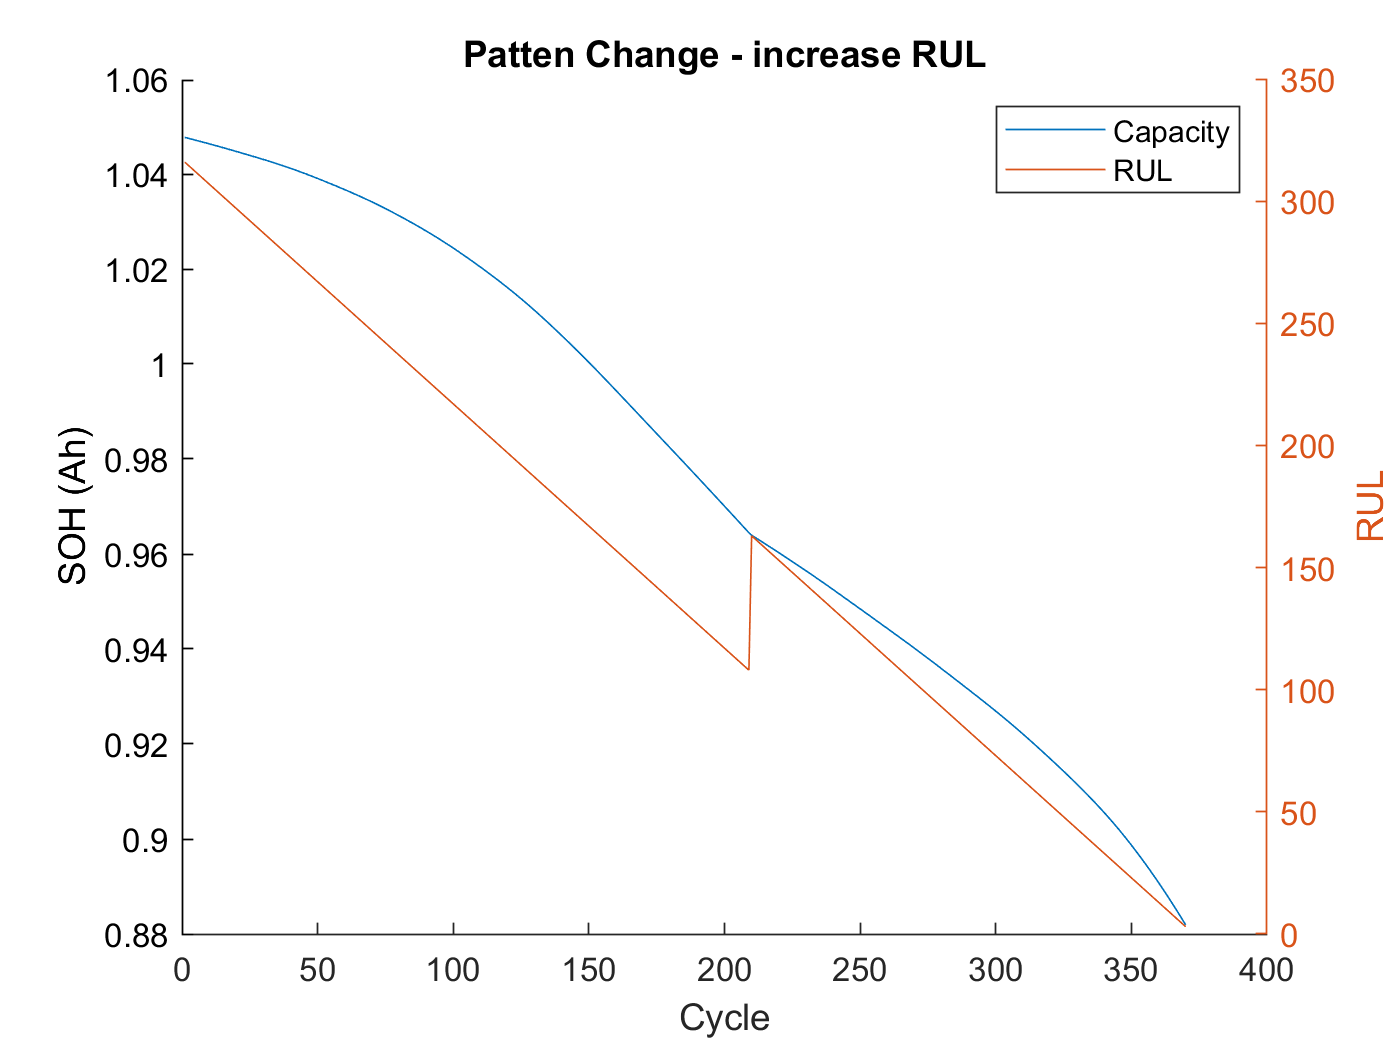

figure
hold on 
plot(Y_soh_ref_to_big2)
ylabel('SOH (Ah)')
yyaxis right
ylabel('RUL')
plot(Y_ref_to_big2)
hold off
xlabel('Cycle')
title('Patten Change - increase RUL')
legend_str = cell(2,1);
legend_str{1} = 'Capacity';
legend_str{2} = 'RUL';
legend(legend_str)


if gen_header

ryan4_util_gen_header(xnorm_ref            ,ynorm_ref           ,Y_ref                     ,22 ) ; 
ryan4_util_gen_header(xnorm_small          ,ynorm_small         ,Y_small                   ,11 ) ; 
ryan4_util_gen_header(xnorm_big            ,ynorm_big           ,Y_big                     ,33 ) ; 
ryan4_util_gen_header(xnorm_ref_to_small   ,ynorm_ref_to_small  ,Y_ref_to_small            ,21 ) ; 
ryan4_util_gen_header(xnorm_ref_to_big     ,ynorm_ref_to_big    ,Y_ref_to_big              ,23 ) ; 
ryan4_util_gen_header(xnorm_ref_to_small2   ,ynorm_ref_to_small2  ,Y_ref_to_small2         ,211 ) ; 
ryan4_util_gen_header(xnorm_ref_to_big2     ,ynorm_ref_to_big2    ,Y_ref_to_big2           ,233 ) ; 


ryan4_util_gen_header(xnorm_1   ,ynorm_1   ,Y_1  ,1  )
ryan4_util_gen_header(xnorm_2   ,ynorm_2   ,Y_2  ,2  )
ryan4_util_gen_header(xnorm_3   ,ynorm_3   ,Y_3  ,3  )
ryan4_util_gen_header(xnorm_4   ,ynorm_4   ,Y_4  ,4  )
ryan4_util_gen_header(xnorm_5   ,ynorm_5   ,Y_5  ,5  )
ryan4_util_gen_header(xnorm_6   ,ynorm_6   ,Y_6  ,6  )
ryan4_util_gen_header(xnorm_7   ,ynorm_7   ,Y_7  ,7  )
ryan4_util_gen_header(xnorm_8   ,ynorm_8   ,Y_8  ,8  )
ryan4_util_gen_header(xnorm_9   ,ynorm_9   ,Y_9  ,9  )
ryan4_util_gen_header(xnorm_10  ,ynorm_10  ,Y_10 ,10 )
ryan4_util_gen_header(xnorm_11  ,ynorm_11  ,Y_11 ,11 )
ryan4_util_gen_header(xnorm_12  ,ynorm_12  ,Y_12 ,12 )

end



if save_data

save('ryan4_data.mat','idx1change',  '-append');
save('ryan4_data.mat','idx2change',  '-append');
save('ryan4_data.mat','idx3change',  '-append');

save('ryan4_data.mat','scenario_7_test_data_2_SOH',  '-append');
save('ryan4_data.mat','scenario_7_test_data_2_bestMatch_SOH',  '-append');
save('ryan4_data.mat','scenario_7_test_data_2_2ndMatch_SOH',  '-append');

save('ryan4_data.mat','scenario_7_test_data_2_RUL',  '-append');
save('ryan4_data.mat','scenario_7_test_data_2_bestMatch_RUL',  '-append');
save('ryan4_data.mat','scenario_7_test_data_2_2ndMatch_RUL',  '-append');


save('ryan4_data.mat','ynorm_1',  '-append');
save('ryan4_data.mat','ynorm_2',  '-append');
save('ryan4_data.mat','ynorm_3',  '-append');
save('ryan4_data.mat','ynorm_4',  '-append');
save('ryan4_data.mat','ynorm_5',  '-append');
save('ryan4_data.mat','ynorm_6',  '-append');
save('ryan4_data.mat','ynorm_7',  '-append');
save('ryan4_data.mat','ynorm_8',  '-append');
save('ryan4_data.mat','ynorm_9',  '-append');
save('ryan4_data.mat','ynorm_10',  '-append');
save('ryan4_data.mat','ynorm_11',  '-append');
save('ryan4_data.mat','ynorm_12',  '-append');

save('ryan4_data.mat','xnorm_1',  '-append');
save('ryan4_data.mat','xnorm_2',  '-append');
save('ryan4_data.mat','xnorm_3',  '-append');
save('ryan4_data.mat','xnorm_4',  '-append');
save('ryan4_data.mat','xnorm_5',  '-append');
save('ryan4_data.mat','xnorm_6',  '-append');
save('ryan4_data.mat','xnorm_7',  '-append');
save('ryan4_data.mat','xnorm_8',  '-append');
save('ryan4_data.mat','xnorm_9',  '-append');
save('ryan4_data.mat','xnorm_10', '-append');
save('ryan4_data.mat','xnorm_11', '-append');
save('ryan4_data.mat','xnorm_12', '-append');

save('ryan4_data.mat','Y_1',  '-append');
save('ryan4_data.mat','Y_2',  '-append');
save('ryan4_data.mat','Y_3',  '-append');
save('ryan4_data.mat','Y_4',  '-append');
save('ryan4_data.mat','Y_5',  '-append');
save('ryan4_data.mat','Y_6',  '-append');
save('ryan4_data.mat','Y_7',  '-append');
save('ryan4_data.mat','Y_8',  '-append');
save('ryan4_data.mat','Y_9',  '-append');
save('ryan4_data.mat','Y_10', '-append');
save('ryan4_data.mat','Y_11', '-append');
save('ryan4_data.mat','Y_12', '-append');

save('ryan4_data.mat','xnorm_ref','-append');
save('ryan4_data.mat','xnorm_small','-append');
save('ryan4_data.mat','xnorm_big','-append');
save('ryan4_data.mat','xnorm_ref_to_small','-append');
save('ryan4_data.mat','xnorm_ref_to_big','-append');
save('ryan4_data.mat','xnorm_ref_to_small2','-append');
save('ryan4_data.mat','xnorm_ref_to_big2','-append');

save('ryan4_data.mat','ynorm_ref','-append');
save('ryan4_data.mat','ynorm_small','-append');
save('ryan4_data.mat','ynorm_big','-append');
save('ryan4_data.mat','ynorm_ref_to_small','-append');
save('ryan4_data.mat','ynorm_ref_to_big','-append');
save('ryan4_data.mat','ynorm_ref_to_small2','-append');
save('ryan4_data.mat','ynorm_ref_to_big2','-append');

save('ryan4_data.mat','Y_ref','-append');
save('ryan4_data.mat','Y_small','-append');
save('ryan4_data.mat','Y_big','-append');
save('ryan4_data.mat','Y_ref_to_small','-append');
save('ryan4_data.mat','Y_ref_to_big','-append');
save('ryan4_data.mat','Y_ref_to_small2','-append');
save('ryan4_data.mat','Y_ref_to_big2','-append');

save('ryan4_data.mat','Y_soh_ref','-append');
save('ryan4_data.mat','Y_soh_small','-append');
save('ryan4_data.mat','Y_soh_big','-append');

save('ryan4_data.mat','ynorm_soh_ref_to_small2','-append');
save('ryan4_data.mat','ynorm_soh_ref_to_big2','-append');
save('ryan4_data.mat','Y_soh_ref_to_small2','-append');
save('ryan4_data.mat','Y_soh_ref_to_big2','-append');

end